# Data Processing - User Pattern

clear % 이전 그래프는 지우지 않는다.
clear all 
close all %  이전 그래프는 지운다.
load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat
load B0034.mat
load B0036.mat

cap05 = extract_discharge(B0005);
cap06 = extract_discharge(B0006);
cap07 = extract_discharge(B0007);
cap18 = extract_discharge(B0018);
cap34 = extract_discharge(B0034);
cap36 = extract_discharge(B0036);

% A set of four Li-ion batteries (# 5, 6, 7 and 18) 
% were run through 3 different operational profiles (charge, discharge and impedance) at room temperature. 
% Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. 
% Discharge was carried out at a constant current (CC) level of 2A 
% until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively. 
% Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 30% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).


#### room temperature (24 deg C) /  CC Load  (4A,4A,2A)  / 2.0V , 2.2V , 2.7V = 33번 측정이상이 있음.

Data Description:

A set of three Li-ion batteries (# 33, 34 and 36) were run through 3 different operational profiles (charge, discharge and impedance) at room temperature (24 deg C). Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at **4A** until the battery voltage fell to 2.0V and 2.2V for batteries 33 and 34 respectively. For **battery 36 discharge was done at 2A until voltage fell to 2.7V**. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. The experiments were carried out until the capacity had reduced to 1.6Ahr (20% fade).

Files:

B0033.mat	Data for Battery #33

B0034.mat	Data for Battery #34

B0036.mat	Data for Battery #36

pattern_CC_amps = 2;
pattern_restTimeHour = 1; % dynamic 

pattern_dVolt_const05 = 4.2-2.7; % driving range
pattern_CC_amps05 = 2;
pattern_restTimeHour05 = 1; % dynamic 

pattern_dVolt_const06 = 4.2-2.5; % driving range
pattern_CC_amps06 = 2;
pattern_restTimeHour06 = 1; % dynamic 

pattern_dVolt_const07 = 4.2-2.2; % driving range
pattern_CC_amps07 = 2;
pattern_restTimeHour07 = 1; % dynamic 

pattern_dVolt_const18 = 4.2-2.5; % driving range
pattern_CC_amps18 = 2;
pattern_restTimeHour18 = 1; % dynamic 

%  (24 deg C). 
% Charging was carried out in a constant current (CC) mode at 1.5A 
% until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode 
% until the charge current dropped to 20mA. 
% Discharge was carried out at 4A until the battery voltage fell to 2.0V and 2.2V 
% for batteries 33 and 34 respectively. 
% For battery 36 discharge was done at 2A until voltage fell to 2.7V. 
pattern_dVolt_const33 = 4.2-2.0; % driving range
pattern_CC_amps33 = 4;
pattern_restTimeHour33 = 1; % dynamic 

pattern_dVolt_const34 = 4.2-2.2; % driving range
pattern_CC_amps34 = 4;
pattern_restTimeHour34 = 1; % dynamic 

pattern_dVolt_const36 = 4.2-2.7; % driving range
pattern_CC_amps36 = 2;
pattern_restTimeHour36 = 1; % dynamic 


%result = [cap',cycleTimeHour',restTimeHour',restCycle',cTempMax',cTempMaxDt',cCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',dTempMaxDt',dCcEndTimeSec' ];
%result = [cap',cycleTimeHourHour',restTimeHourHour',restCycle',cTempMax',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',cCcEndTimeSec',dCcEndTimeSec' ];
%result = [cap',cycleTimeHour',restTimeHour',restCycle',cTempMax',cCcEndTimeSec',dTempMax',dCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe' ];

i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;

result05_ = extract_feature_all_v2(B0005,0,cap05);
% https://kr.mathworks.com/matlabcentral/answers/269056-how-to-initialize-a-row-vector-with-value-zero-of-size-1xn
pattern_dVolt05_vector = ones(length(result05_),1) * pattern_dVolt_const05; 
result05 = [result05_ pattern_dVolt05_vector];



i = 1;
capacity05 = result05(:,i)'; i=i+1;
cycleTimeHour05 = result05(:,i)'; i=i+1;
restTimeHour05 = result05(:,i)'; i=i+1;
restCycle05 = result05(:,i)'; i=i+1;
cTempMax05 = result05(:,i)'; i=i+1;
cCcEndTimeSec05 = result05(:,i)'; i=i+1;
ohm05  = result05(:,i)'; i=i+1;
re_c05 =  result05(:,i)'; i=i+1;
re_d05 = result05(:,i)'; i=i+1;
cycleNoChageRe05 = result05(:,i)'; i=i+1;
cycleNoDischageRe05 = result05(:,i)'; i=i+1;
dTempMax05 = result05(:,i)'; i=i+1;
dCcEndTimeSec05 = result05(:,i)'; i=i+1;
pattern_dVolt05 = result05(:,i)'; i=i+1;

%%
result06_ = extract_feature_all_v2(B0006,0,cap06);
pattern_dVolt06_vector = ones(length(result06_),1) * pattern_dVolt_const06; 
result06 = [result06_ pattern_dVolt06_vector];

i = 1;
capacity06 = result06(:,i)'; i=i+1;
cycleTimeHour06 = result06(:,i)'; i=i+1;
restTimeHour06 = result06(:,i)'; i=i+1;
restCycle06 = result06(:,i)'; i=i+1;
cTempMax06 = result06(:,i)'; i=i+1;
cCcEndTimeSec06 = result06(:,i)'; i=i+1;
ohm06  = result06(:,i)'; i=i+1;
re_c06 =  result06(:,i)'; i=i+1;
re_d06 = result06(:,i)'; i=i+1;
cycleNoChageRe06 = result06(:,i)'; i=i+1;
cycleNoDischageRe06 = result06(:,i)'; i=i+1;
dTempMax06 = result06(:,i)'; i=i+1;
dCcEndTimeSec06 = result06(:,i)'; i=i+1;
pattern_dVolt06 = result06(:,i)'; i=i+1;

%%
result07_ = extract_feature_all_v2(B0007,0,cap07);
pattern_dVolt07_vector = ones(length(result07_),1) * pattern_dVolt_const07; 
result07 = [result07_ pattern_dVolt07_vector];

i = 1;
capacity07 = result07(:,i)'; i=i+1;
cycleTimeHour07 = result07(:,i)'; i=i+1;
restTimeHour07 = result07(:,i)'; i=i+1;
restCycle07 = result07(:,i)'; i=i+1;
cTempMax07 = result07(:,i)'; i=i+1;
cCcEndTimeSec07 = result07(:,i)'; i=i+1;
ohm07  = result07(:,i)'; i=i+1;
re_c07 =  result07(:,i)'; i=i+1;
re_d07 = result07(:,i)'; i=i+1;
cycleNoChageRe07 = result07(:,i)'; i=i+1;
cycleNoDischageRe07 = result07(:,i)'; i=i+1;
dTempMax07 = result07(:,i)'; i=i+1;
dCcEndTimeSec07 = result07(:,i)'; i=i+1;
pattern_dVolt07 = result07(:,i)'; i=i+1;

%%
result18_ = extract_feature_all_v2(B0018,0,cap18);
pattern_dVolt18_vector = ones(length(result18_),1) * pattern_dVolt_const18; 
result18 = [result18_ pattern_dVolt18_vector];
i = 1;
capacity18 = result18(:,i)'; i=i+1;
cycleTimeHour18 = result18(:,i)'; i=i+1;
restTimeHour18 = result18(:,i)'; i=i+1;
restCycle18 = result18(:,i)'; i=i+1;
cTempMax18 = result18(:,i)'; i=i+1;
cCcEndTimeSec18 = result18(:,i)'; i=i+1;
ohm18  = result18(:,i)'; i=i+1;
re_c18 =  result18(:,i)'; i=i+1;
re_d18 = result18(:,i)'; i=i+1;
cycleNoChageRe18 = result18(:,i)'; i=i+1;
cycleNoDischageRe18 = result18(:,i)'; i=i+1;
dTempMax18 = result18(:,i)'; i=i+1;
dCcEndTimeSec18 = result18(:,i)'; i=i+1;
pattern_dVolt18 = result18(:,i)'; i=i+1;

%%
result34_ = extract_feature_all_v2(B0034,0,cap34);
pattern_dVolt34_vector = ones(length(result34_),1) * pattern_dVolt_const34; 
result34 = [result34_ pattern_dVolt34_vector];
i = 1;
capacity34 = result34(:,i)'; i=i+1;
cycleTimeHour34 = result34(:,i)'; i=i+1;
restTimeHour34 = result34(:,i)'; i=i+1;
restCycle34 = result34(:,i)'; i=i+1;
cTempMax34 = result34(:,i)'; i=i+1;
cCcEndTimeSec34 = result34(:,i)'; i=i+1;
ohm34  = result34(:,i)'; i=i+1;
re_c34 =  result34(:,i)'; i=i+1;
re_d34 = result34(:,i)'; i=i+1;
cycleNoChageRe34 = result34(:,i)'; i=i+1;
cycleNoDischageRe34 = result34(:,i)'; i=i+1;
dTempMax34 = result34(:,i)'; i=i+1;
dCcEndTimeSec34 = result34(:,i)'; i=i+1;
pattern_dVolt34 = result34(:,i)'; i=i+1;

result_all = [ result05 ; result06 ; result07 ; result18];
%% org graph - cycle
cycle_number = length(capacity05);

result36_ = extract_feature_all_v2(B0036,0,cap36);
pattern_dVolt36_vector = ones(length(result36_),1) * pattern_dVolt_const36; 
result36 = [result36_ pattern_dVolt36_vector];

i = 1;
capacity36 = result36(:,i)'; i=i+1;
cycleTimeHour36 = result36(:,i)'; i=i+1;
restTimeHour36 = result36(:,i)'; i=i+1;
restCycle36 = result36(:,i)'; i=i+1;
cTempMax36 = result36(:,i)'; i=i+1;
cCcEndTimeSec36 = result36(:,i)'; i=i+1;
ohm36  = result36(:,i)'; i=i+1;
re_c36 =  result36(:,i)'; i=i+1;
re_d36 = result36(:,i)'; i=i+1;
cycleNoChageRe36 = result36(:,i)'; i=i+1;
cycleNoDischageRe36 = result36(:,i)'; i=i+1;
dTempMax36 = result36(:,i)'; i=i+1;
dCcEndTimeSec36 = result36(:,i)'; i=i+1;
pattern_dVolt36 = result36(:,i)'; i=i+1;

% new data set #01 / #02
result05(58,1)

ans = 1.7060

result06(53,1)

ans = 1.7081


% ignore rest time , maxTempDt 
result05_06 = [ result05(1:58,:) ; result06(:,53:end) ]

result05_06 = 	1.0e+03 *

    0.0019    0.0023    0.0023         0    0.0273    0.7713    0.0390    3.3668    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0043    0.0020         0    0.0292    3.3851    0.0390    3.3487    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0086    0.0043         0    0.0293    3.3819    0.0388    3.3293    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0128    0.0043         0    0.0292    3.3721    0.0388    3.3295    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0171    0.0043         0    0.0291    3.3707    0.0387    3.3275    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0215    0.0044    0.0010    0.0290    3.3725    0.0388    3.3290    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0259    0.0044    0.0010    0.0292    3.3749    0.0388    3.3282    0.0000       NaN       NaN    0.0010    0.00

result06_05 = [ result06(1:53,:) ; result05(:,58:end) ]

result06_05 = 	1.0e+03 *

    0.0020    0.0023    0.0023         0    0.0271    0.8579    0.0392    3.6902    0.0000       NaN       NaN    0.0010    0.0010    0.0017
    0.0020    0.0043    0.0020         0    0.0289    3.7233    0.0392    3.6723    0.0000       NaN       NaN    0.0010    0.0010    0.0017
    0.0020    0.0086    0.0043         0    0.0290    3.7192    0.0390    3.6516    0.0000       NaN       NaN    0.0010    0.0010    0.0017
    0.0020    0.0128    0.0043         0    0.0289    3.6841    0.0388    3.6316    0.0000       NaN       NaN    0.0010    0.0010    0.0017
    0.0020    0.0171    0.0043         0    0.0288    3.6453    0.0390    3.6292    0.0000       NaN       NaN    0.0010    0.0010    0.0017
    0.0020    0.0215    0.0044    0.0010    0.0288    3.6469    0.0388    3.6523    0.0000       NaN       NaN    0.0010    0.0010    0.0017
    0.0020    0.0259    0.0044    0.0010    0.0289    3.6117    0.0390    3.6508    0.0000       NaN       NaN    0.0010    0.00

result_05_06_all = [ result05 ; result06 ]

result_05_06_all = 	1.0e+03 *

    0.0019    0.0023    0.0023         0    0.0273    0.7713    0.0390    3.3668    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0043    0.0020         0    0.0292    3.3851    0.0390    3.3487    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0086    0.0043         0    0.0293    3.3819    0.0388    3.3293    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0128    0.0043         0    0.0292    3.3721    0.0388    3.3295    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0171    0.0043         0    0.0291    3.3707    0.0387    3.3275    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0215    0.0044    0.0010    0.0290    3.3725    0.0388    3.3290    0.0000       NaN       NaN    0.0010    0.0010    0.0015
    0.0018    0.0259    0.0044    0.0010    0.0292    3.3749    0.0388    3.3282    0.0000       NaN       NaN    0.0010   

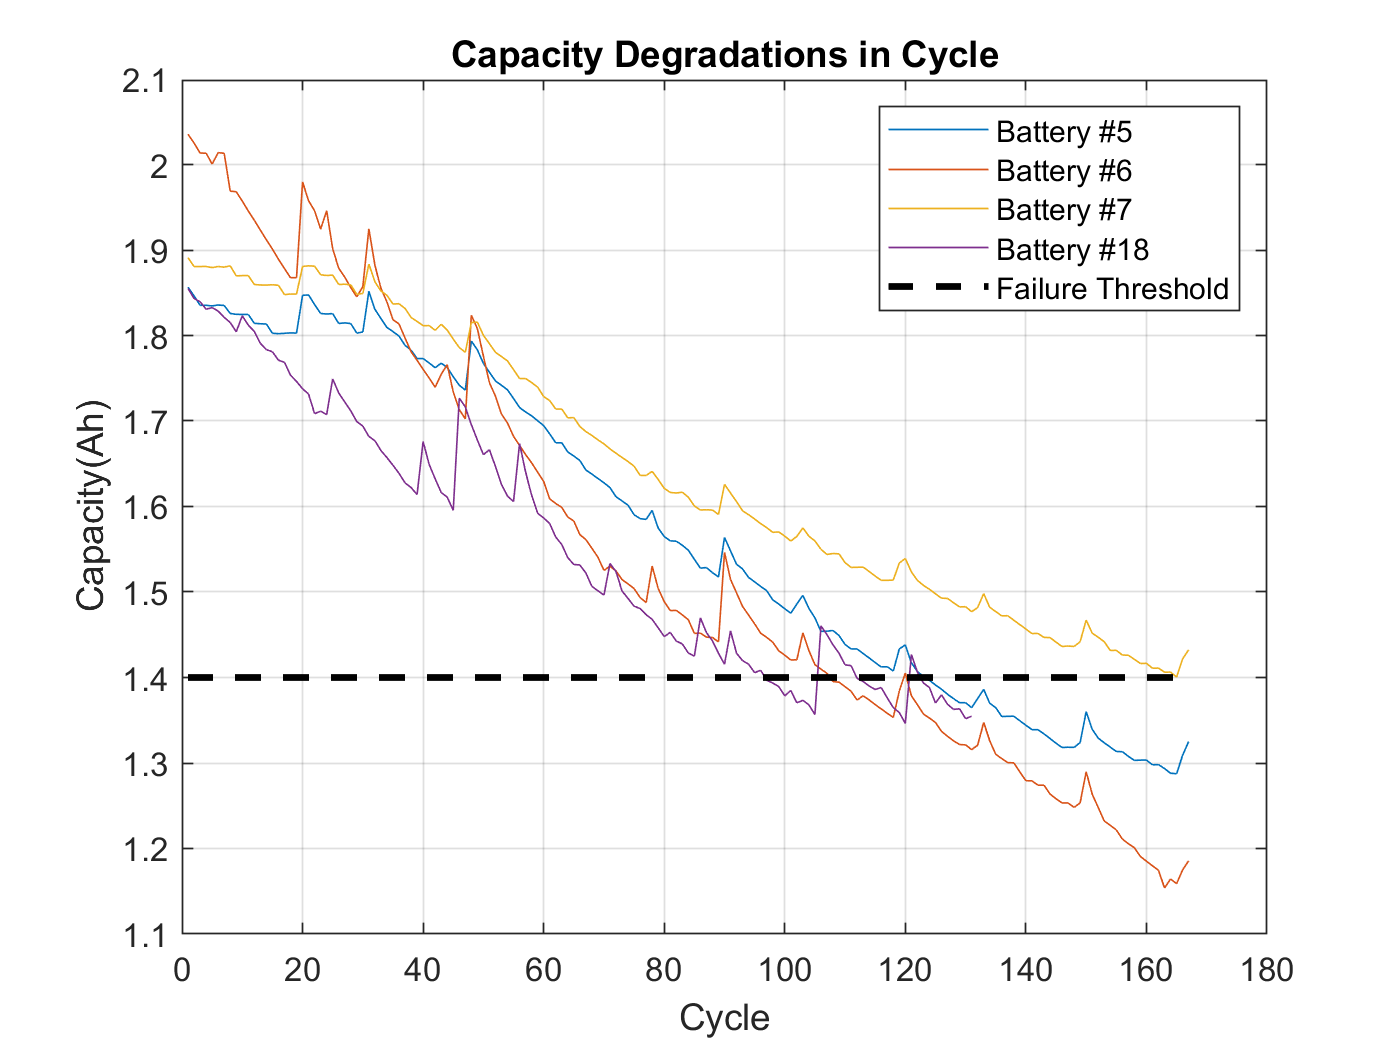




result_all = [ result05 ; result06 ; result07 ; result18];
%% org graph - cycle
cycle_number = length(capacity05);

figure
plot(capacity05), hold on, plot(capacity06), plot(capacity07), plot(capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle')

#6 index 53 (58) 

#5 index 58 (64) 

에서 1.70으로 겹친다.

여기서 두개의 데이타 셋을 만든다.

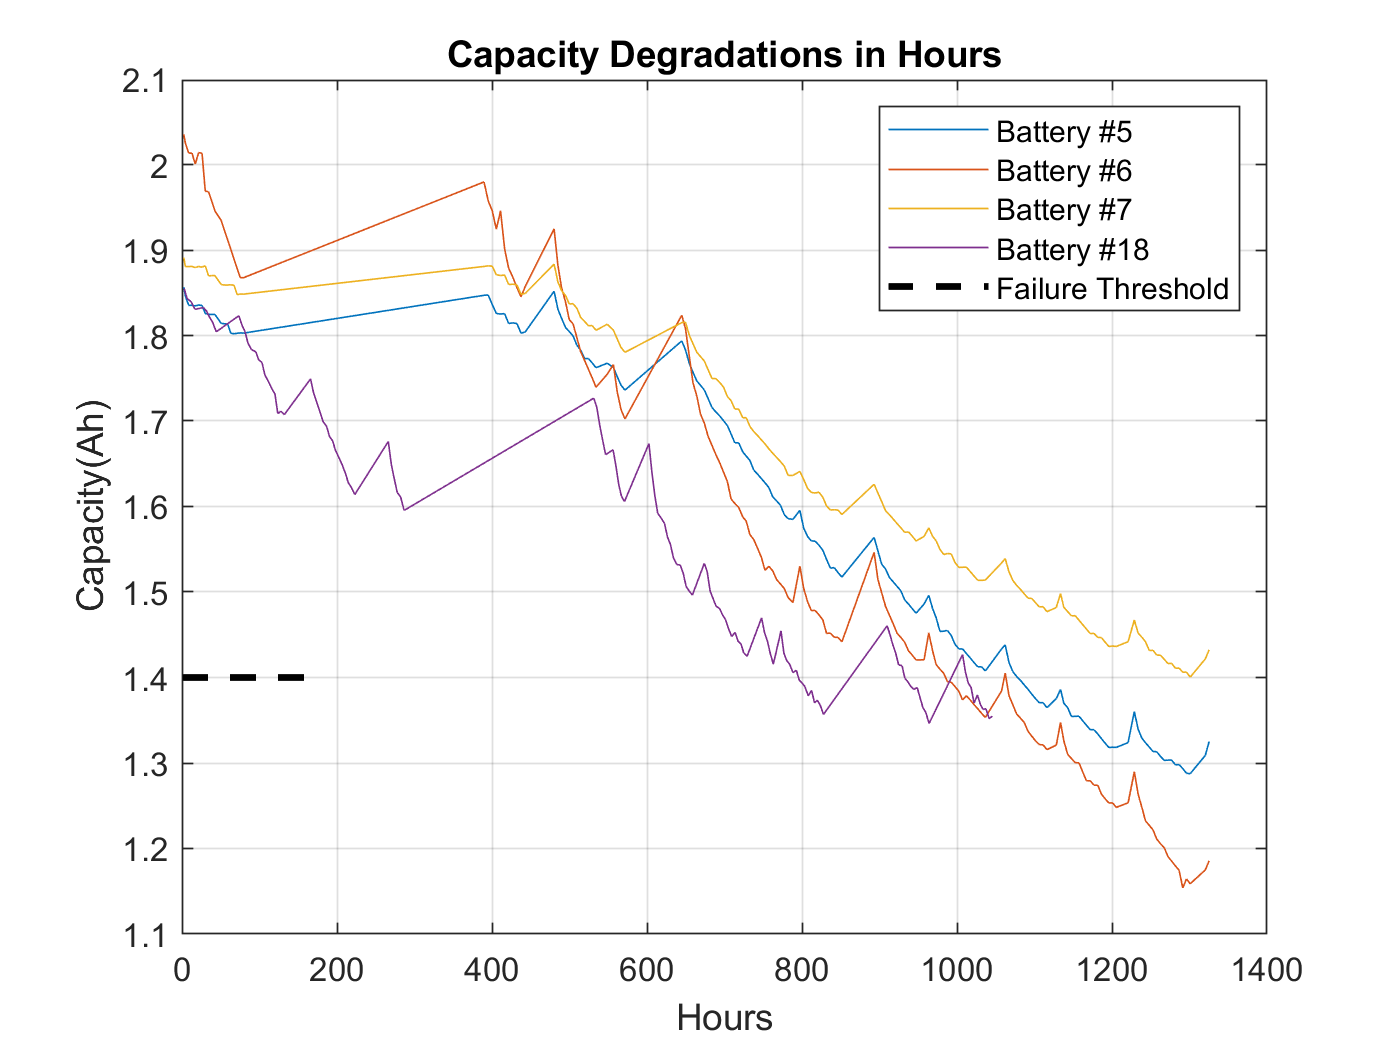

%% org graph -  time 
figure
plot(cycleTimeHour05,capacity05), hold on, plot(cycleTimeHour06,capacity06), plot(cycleTimeHour07,capacity07), plot(cycleTimeHour18,capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Hours, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Hours')

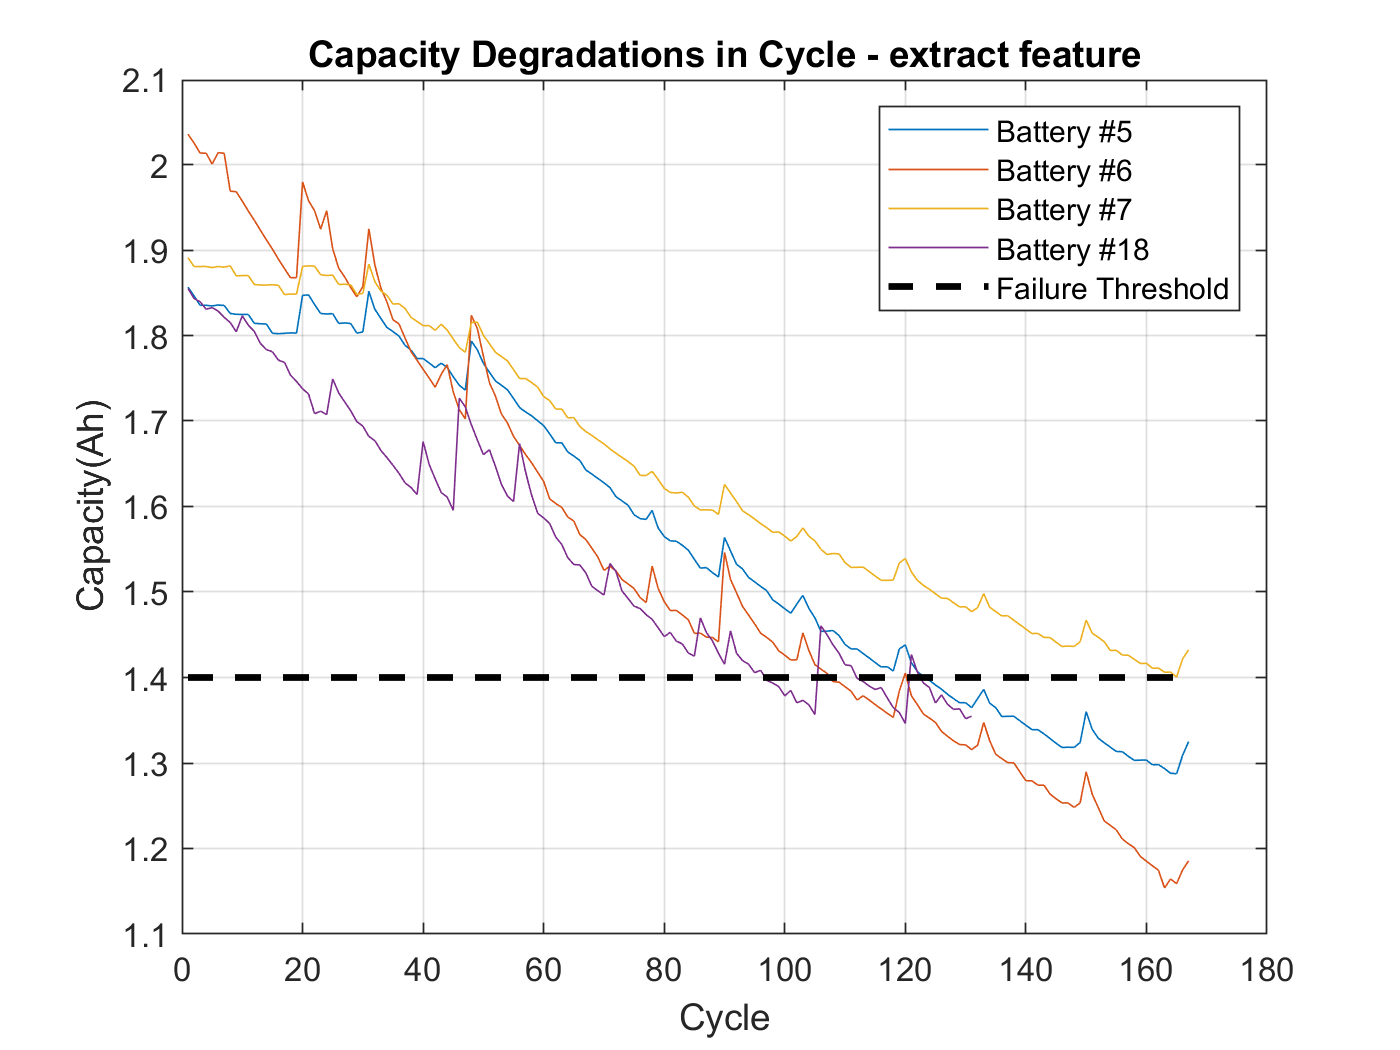


%% new graph using my function - cycle
figure
plot(capacity05), hold on, plot(capacity06), plot(capacity07), plot(capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle - extract feature')

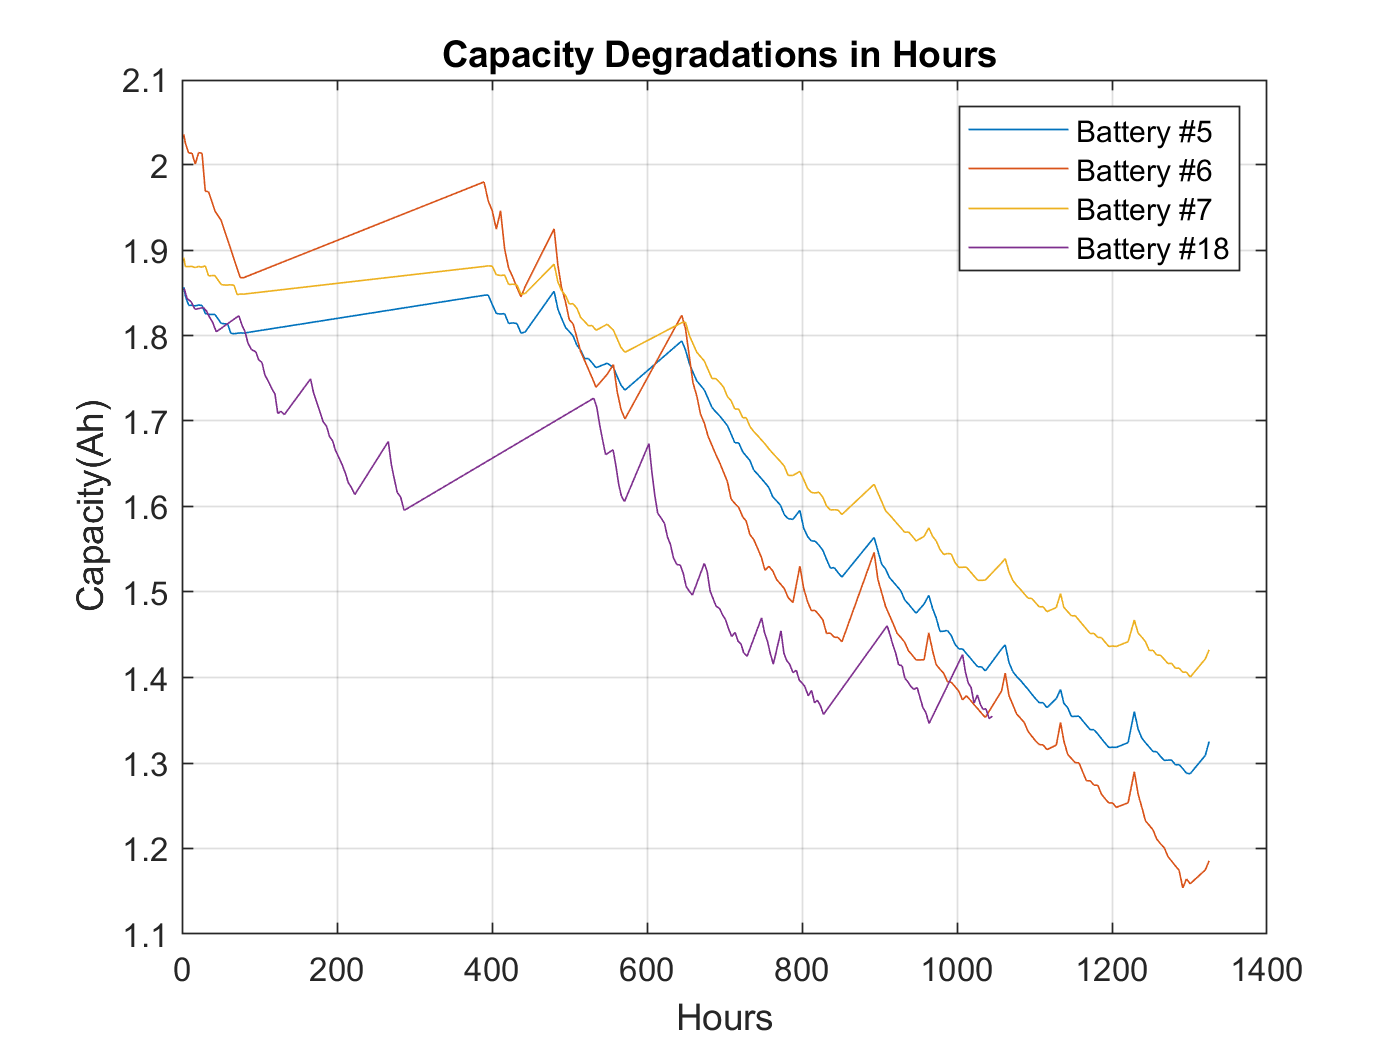


%% new graph using my function - time
figure
plot(cycleTimeHour05,capacity05), hold on, plot(cycleTimeHour06,capacity06), plot(cycleTimeHour07,capacity07), plot(cycleTimeHour18,capacity18)
hold off, grid on
xlabel Hours, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18')
title('Capacity Degradations in Hours ')

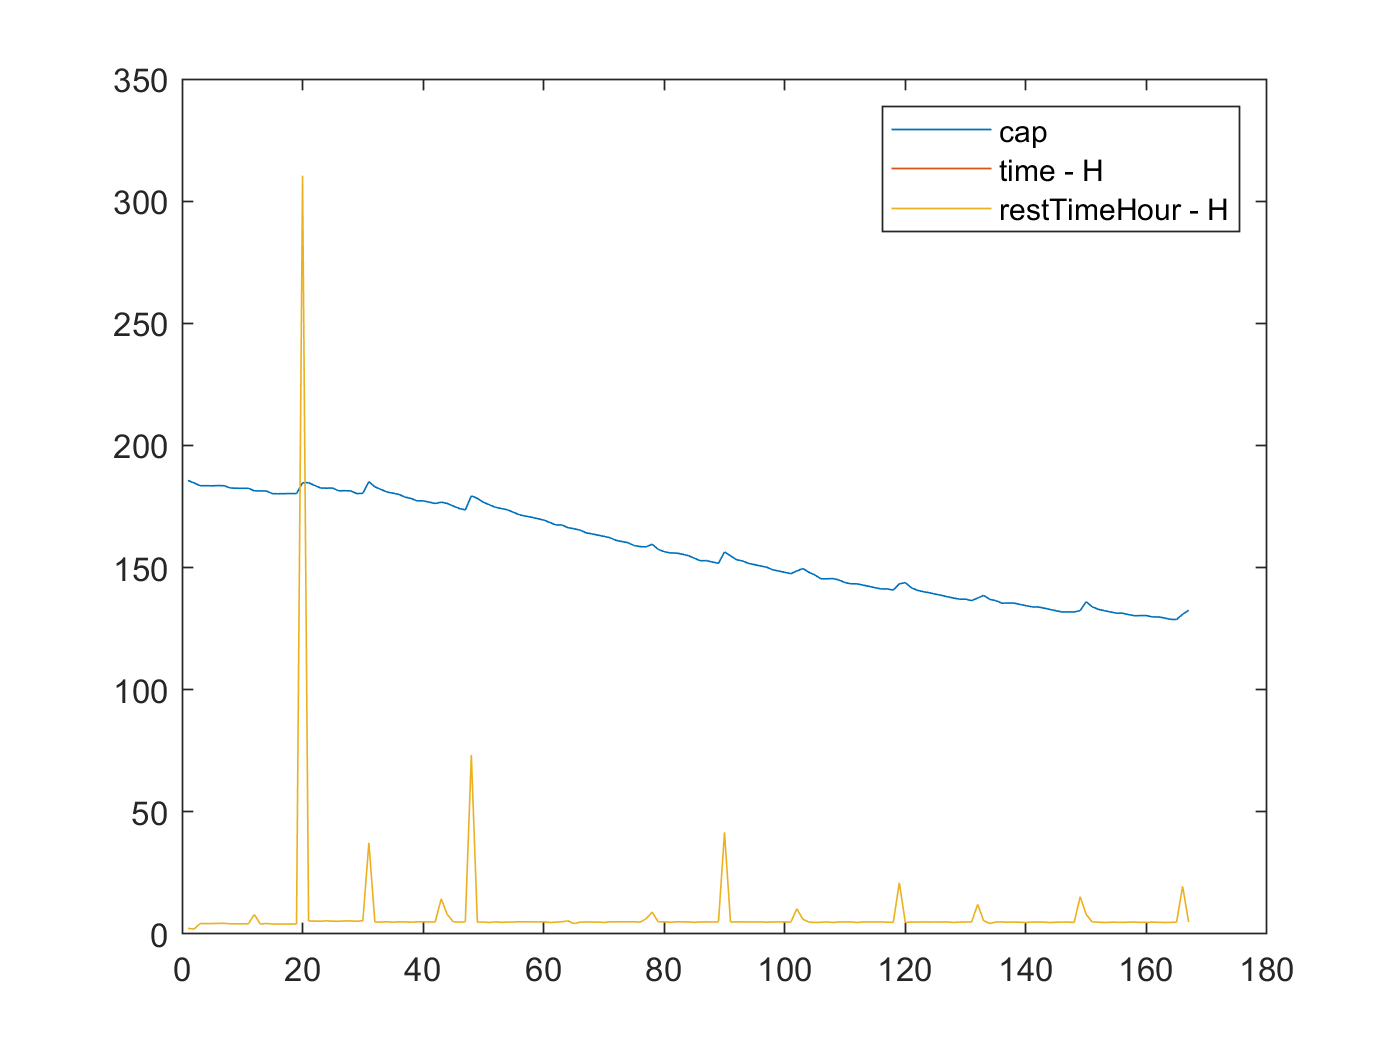

%% check outlier
%% check rest time
% https://kr.mathworks.com/matlabcentral/answers/15672-vector-shift
a = result05(:,1);
b = result05(:,2);
c = zeros(size(b));
n=1; %Shift units
c(n+1:end)=b(1:end-n);
c(1)=0;
d = b - c;
e = result05(:,3);
figure
plot(a.*100)
hold on
plot(d)
plot(e)
legend('cap','time - H ','restTimeHour - H')

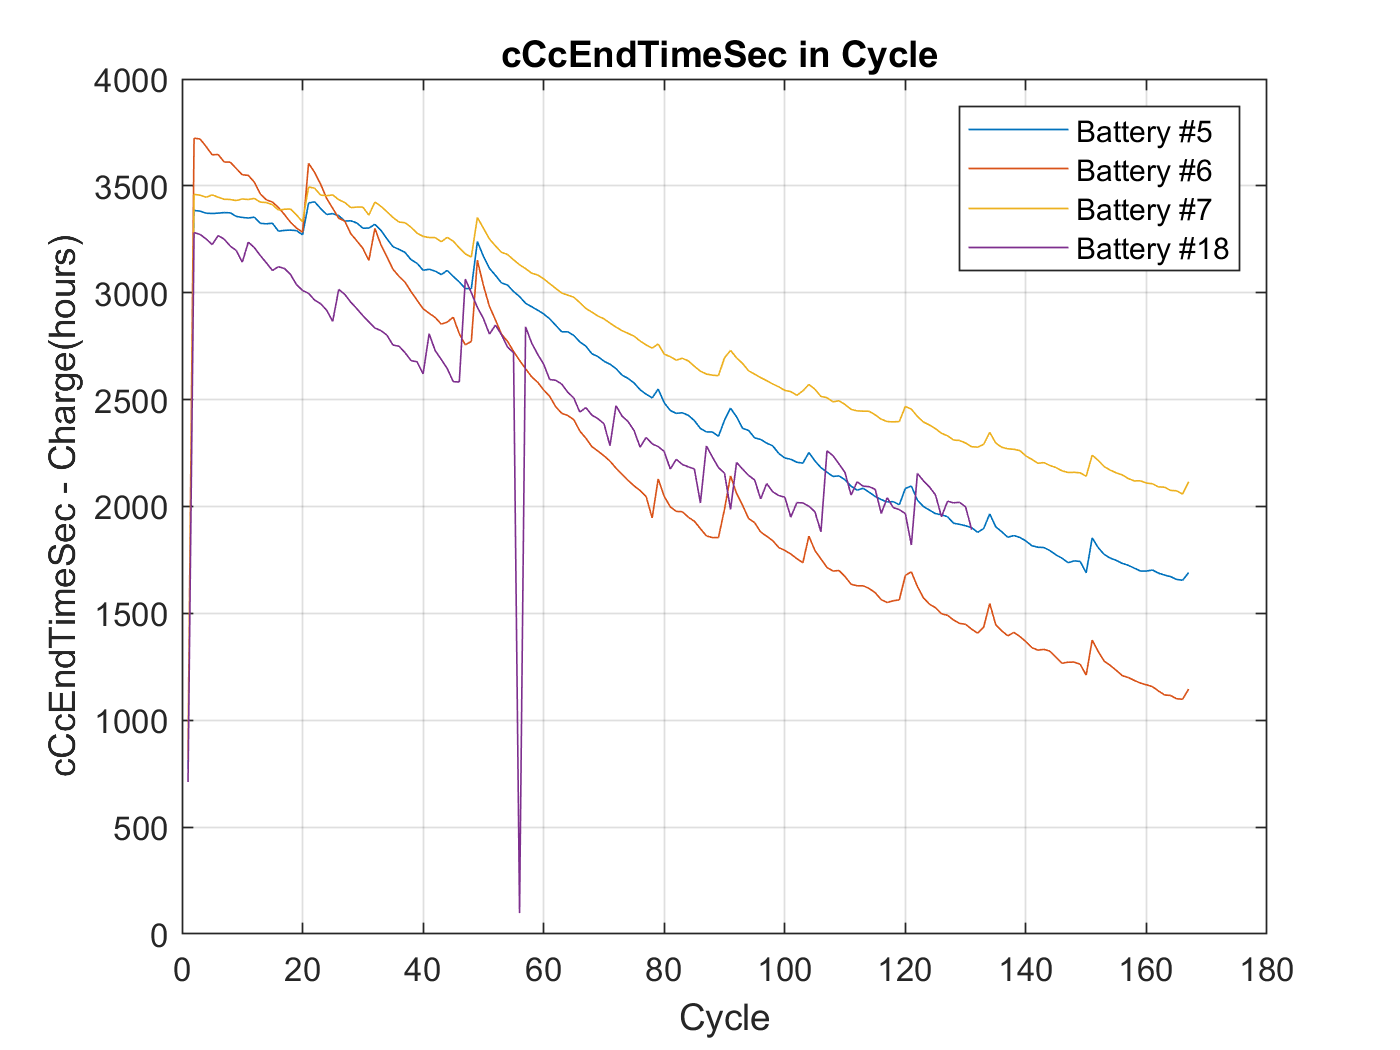

figure
plot(cCcEndTimeSec05), hold on,plot(cCcEndTimeSec06),plot(cCcEndTimeSec07),plot(cCcEndTimeSec18),hold off, grid on
xlabel Cycle, ylabel 'cCcEndTimeSec - Charge(hours)'
%legend('Battery #5', 'Battery #6', 'Battery #7')
legend('Battery #5', 'Battery #6', 'Battery #7','Battery #18')
title('cCcEndTimeSec in Cycle ')

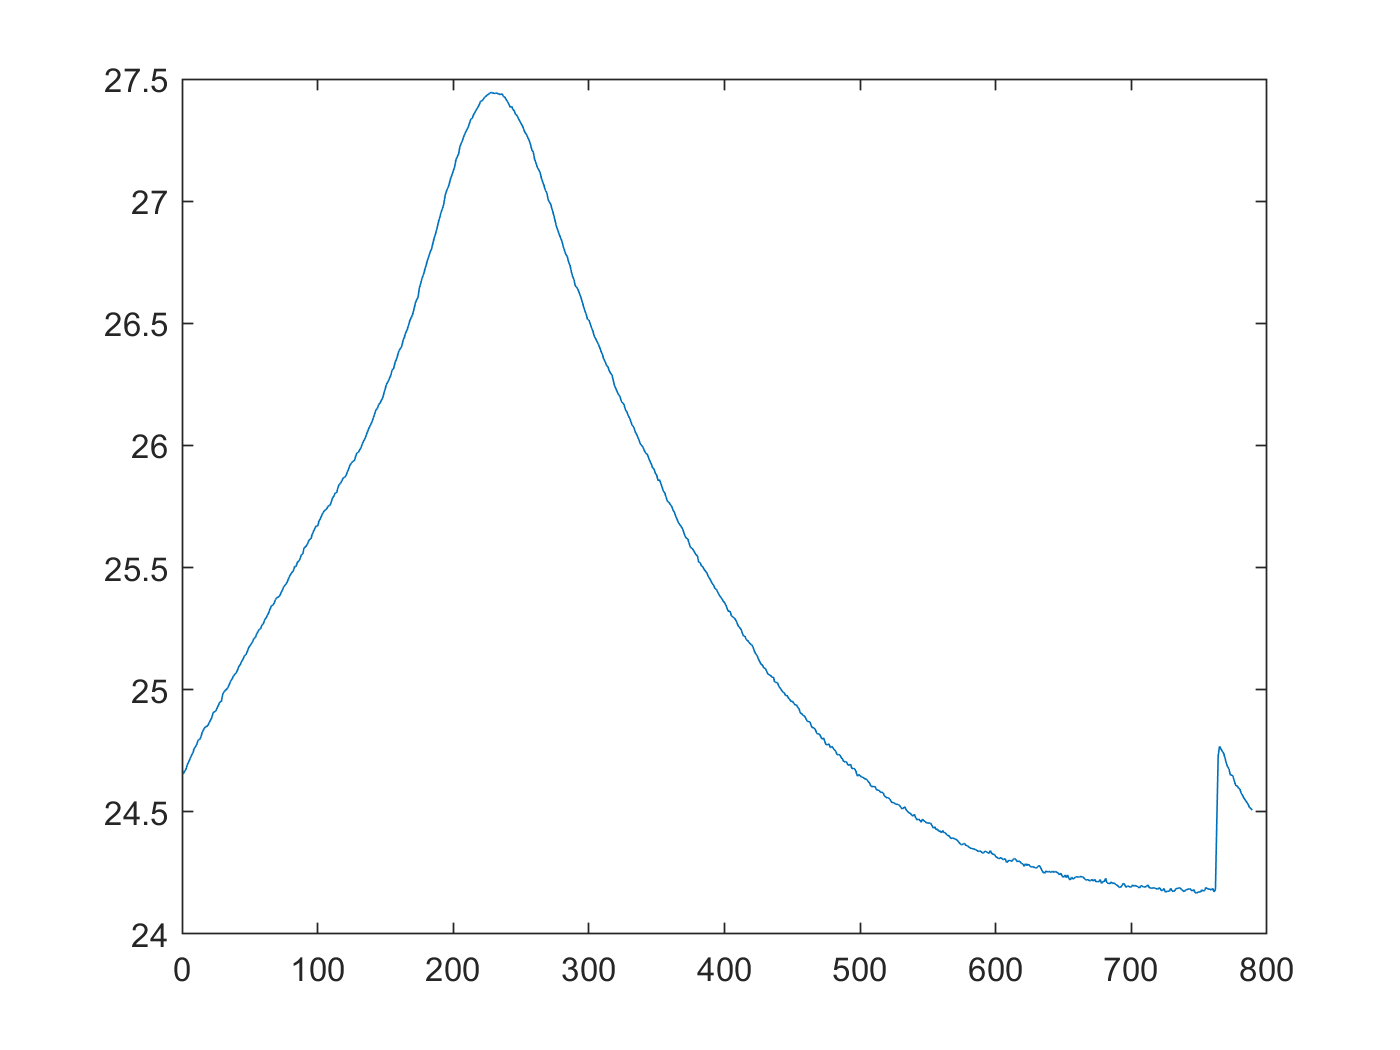


%result = [cap,cTemp,cTime,cV,cI,cVcharge,cIcharge,dTemp,dTime,dV,dI,dIload,icCsense,icCbattery,icCratio,icBatImp,icRecImp,idCsense,idCbattery,idCratio,idBatImp,idRecImp ];
%[cap,cTemp,cTime,cV,cI,cVcharge,cIcharge,dTemp,dTime,dV,dI,dIload,icCsense,icCbattery,icCratio,icBatImp,icRecImp,idCsense,idCbattery,idCratio,idBatImp,idRecImp ] ...
    %= extract_raw_data(B0005,1);
[cap,cTemp,cTime,cV,cI,cVcharge,cIcharge,dTemp,dTime,dV,dI,dIload ] ...
    = extract_raw_data(B0005,1);

figure
plot(cTemp)

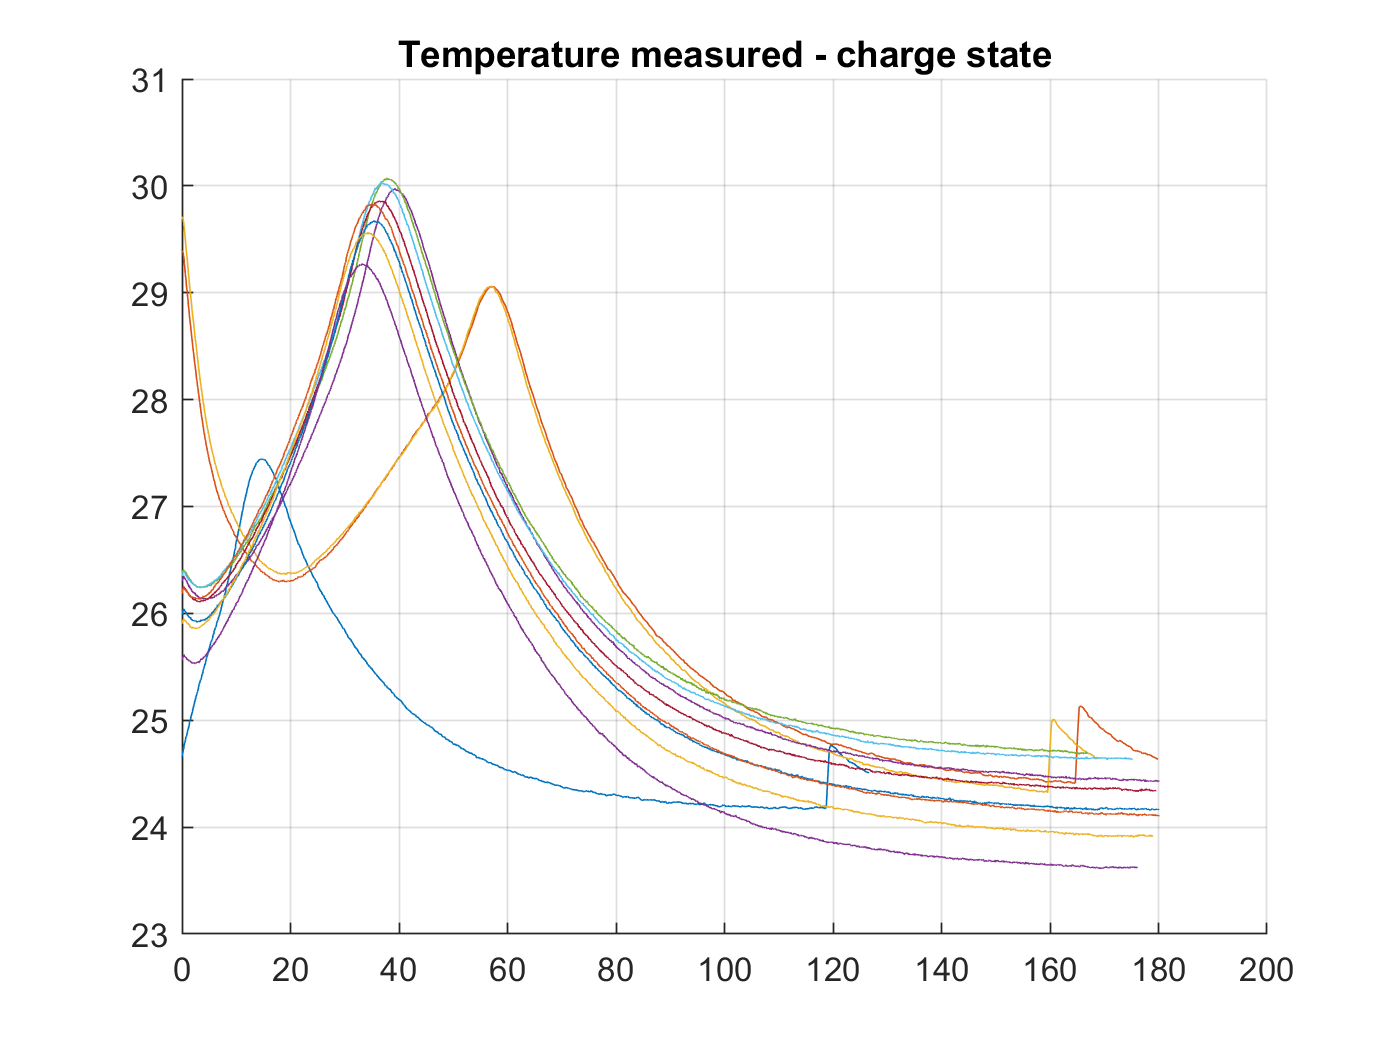



figure
hold on
items = size(B0005.cycle,2);
for i=1:items
    if isequal(B0005.cycle(i).type, 'charge')
        if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Temperature_measured)
        end
    end
end
hold off 
title("Temperature measured - charge state")
grid on

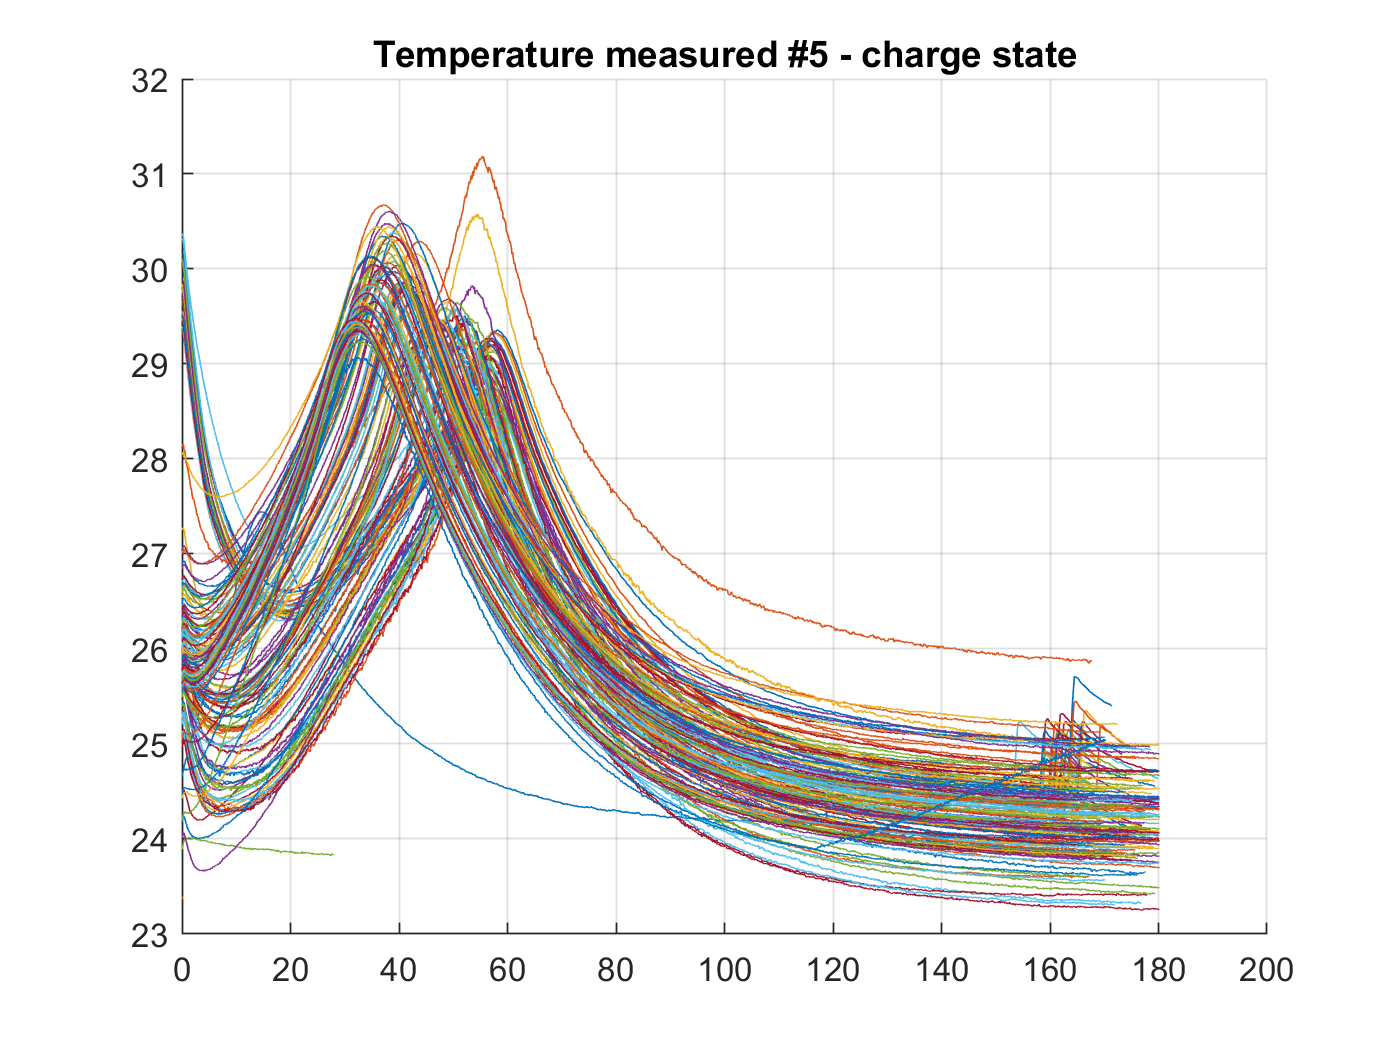


% https://kr.mathworks.com/matlabcentral/fileexchange/21050-varycolor
% https://blogs.mathworks.com/pick/2008/08/15/colors-for-your-multi-line-plots/?from=kr

items = size(B0005.cycle,2);

figure
ColorSet = varycolor(items);
hold all;
for i=1:items
    if isequal(B0005.cycle(i).type, 'charge')
        %if mod(i , 10 ) == 1
            k = mod (round(i / 10), 10 ) + 1;
            plot(B0005.cycle(i).data.Time/60,B0005.cycle(i).data.Temperature_measured)
        %end
    end
end
hold off 
title("Temperature measured #5 - charge state")
grid on


temp_B18_19 = B0018.cycle(19).data.Temperature_measured

temp_B18_19 =    36.1867   36.1535   36.1301   36.1127   36.0760   36.0429   36.0002   35.9569   35.9040   35.8626   35.8118   35.7616   35.7143   35.6644   35.6151   35.5730   35.5239   35.4833   35.4340   35.3837   35.3436   35.2929   35.2360   35.1931   35.1531   35.1061   35.0537   35.0122   34.9617   34.9027   34.8544   34.8043   34.7614   34.7192   34.6788   34.6349   34.5852   34.5412   34.4930   34.4541   34.3987   34.3659   34.3115   34.2694   34.2279   34.1767   34.1279   34.0850   34.0493   34.0011




items = size(B0018.cycle,2);
cTempMaxIndex = [];


figure
ColorSet = varycolor(items);
hold all;
k=1

k = 1

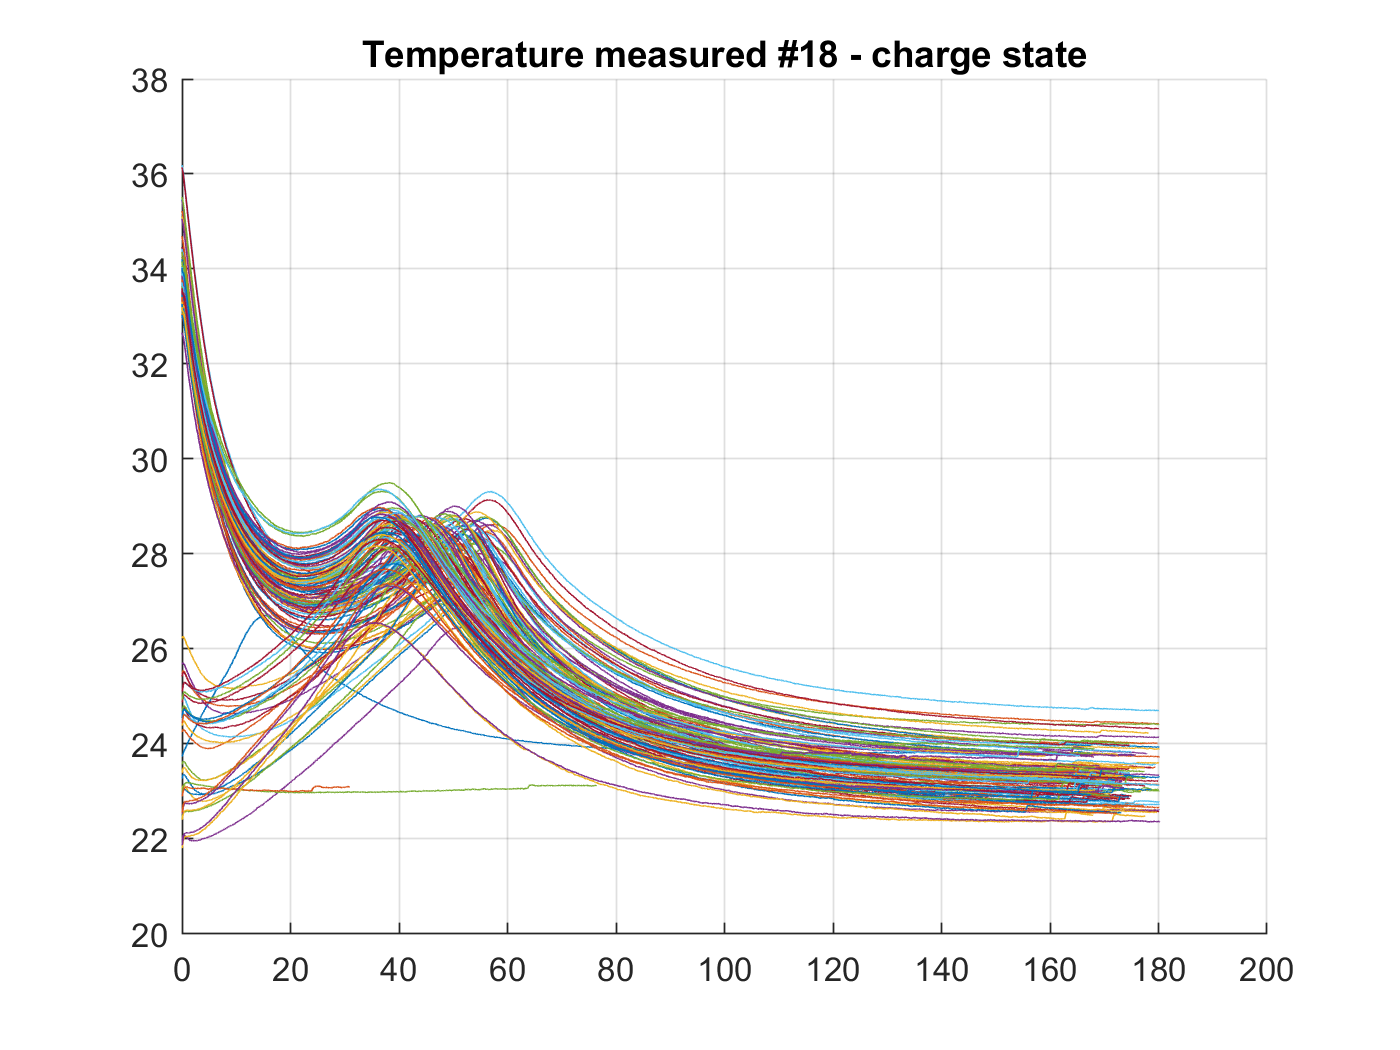

for i=1:items
    if isequal(B0018.cycle(i).type, 'charge')
        %if mod(i , 10 ) == 1
            %k = mod (round(i / 10), 10 ) + 1;
            plot(B0018.cycle(i).data.Time/60, B0018.cycle(i).data.Temperature_measured)
            temp = B0018.cycle(i).data.Temperature_measured;
            cTempMaxGuess = islocalmax(temp,'MinProminence',2);
            if sum(cTempMaxGuess(:) == 1 ) == 0 
               cTempMaxGuess = islocalmax(temp,'MinProminence',1);
            end
            
            if sum(cTempMaxGuess(:) == 1 ) == 0 
                smoothed = smoothdata(B0018.cycle(i).data.Temperature_measured);
                cTempMaxGuess = islocalmax(smoothed,'MinProminence',2);
                if sum(cTempMaxGuess(:) == 1 ) == 0 
                   cTempMaxGuess = islocalmax(smoothed,'MinProminence',1);
                end
            end

            if sum(cTempMaxGuess(:) == 1 ) == 0 
                cTempMaxIndex(k) = max(temp);            
            else 
                cTempMaxIndex(k) = find(cTempMaxGuess, 1, 'first');  
            end
            k = k+1;
        %end
    end
end
hold off 
title("Temperature measured #18 - charge state")
grid on

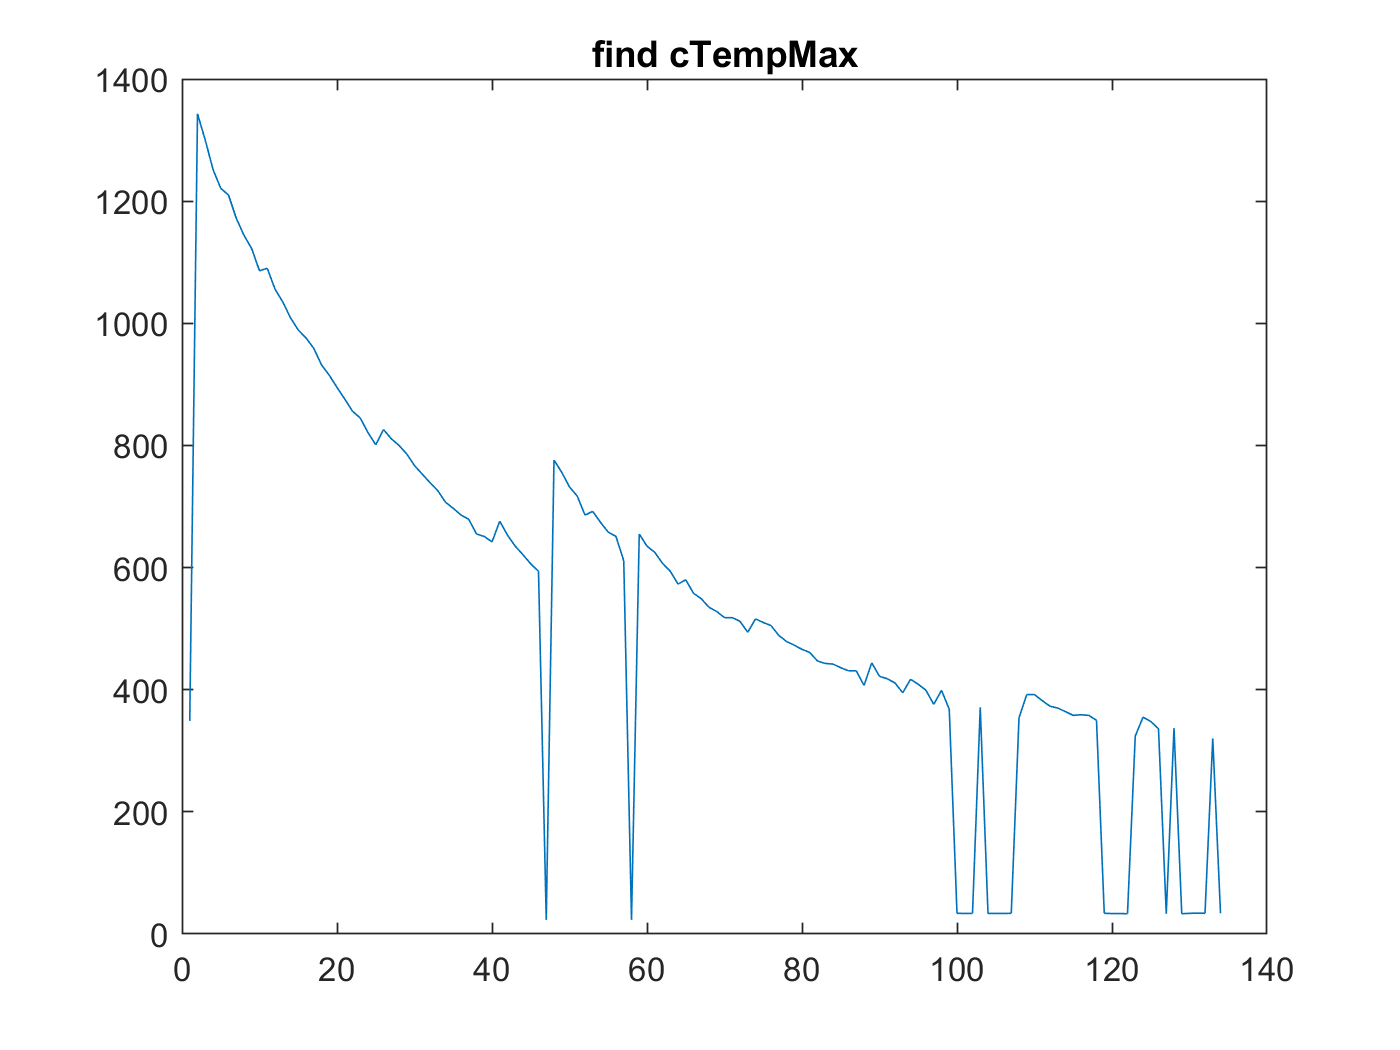

figure
%plot(cTempMaxGuess)
%hold on
%yyaxis("right")
plot(cTempMaxIndex)
hold off
title("find cTempMax")

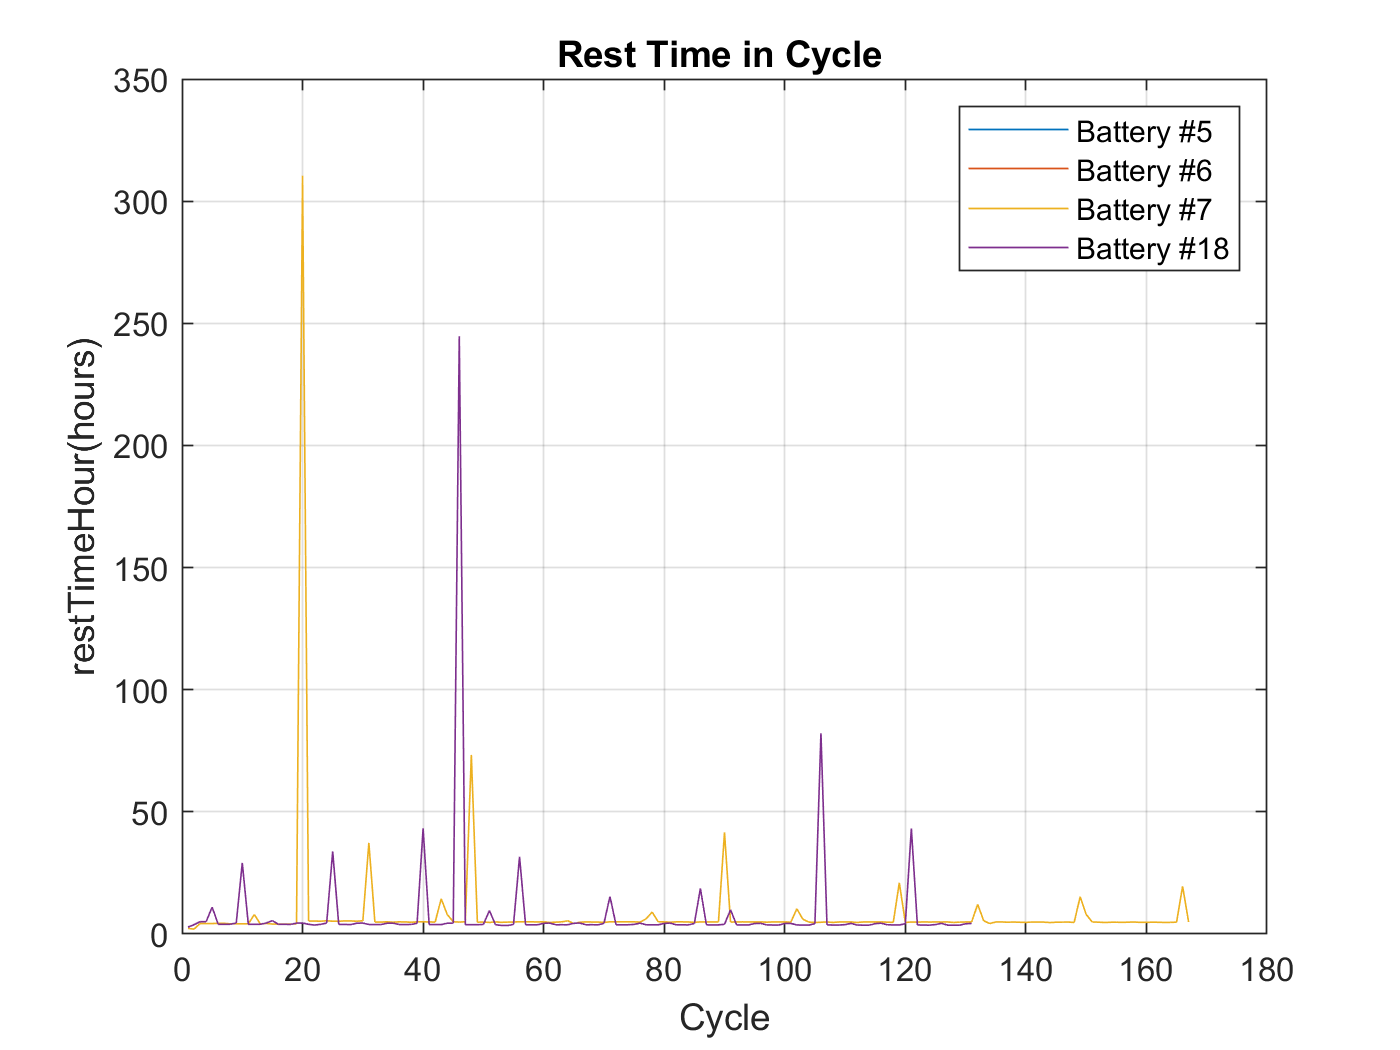

%% rest time   - cycle
use_plot = true; %false;
% battery 18번이 한번 큰 rest time을 가져서 그래프로 보기 힘들다.
figure
if use_plot
    %plot(restTimeHour05), hold on, plot(restTimeHour06), plot(restTimeHour07)
    % plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
    plot(restTimeHour05), hold on, plot(restTimeHour06), plot(restTimeHour07),plot(restTimeHour18)
else
    bar(restTimeHour05), hold on, bar(restTimeHour06), bar(restTimeHour07),bar(restTimeHour18)
end
hold off, grid on
xlabel Cycle, ylabel restTimeHour(hours)
%legend('Battery #5', 'Battery #6', 'Battery #7')
legend('Battery #5', 'Battery #6', 'Battery #7','Battery #18')
title('Rest Time in Cycle ')

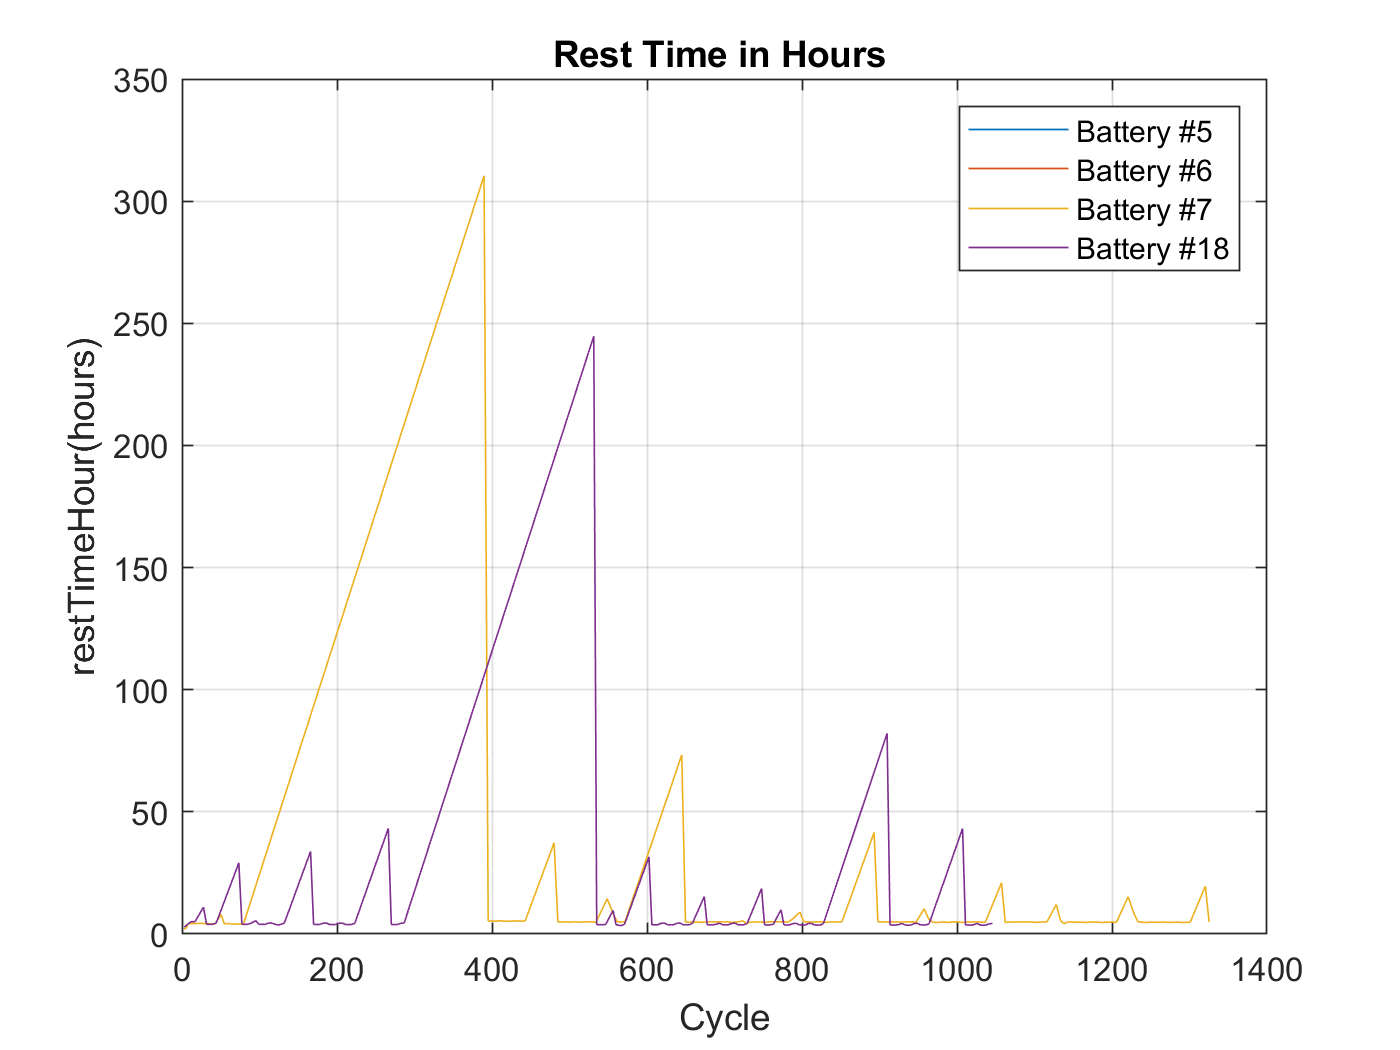


%% rest time   - time
figure
if use_plot
    %plot(cycleTimeHour05,restTimeHour05), hold on, plot(cycleTimeHour06,restTimeHour06), plot(cycleTimeHour07,restTimeHour07)
    % plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
    plot(cycleTimeHour05,restTimeHour05), hold on, plot(cycleTimeHour06,restTimeHour06), plot(cycleTimeHour07,restTimeHour07),plot(cycleTimeHour18,restTimeHour18)
else
    bar(cycleTimeHour05,restTimeHour05), hold on, bar(cycleTimeHour06,restTimeHour06), bar(cycleTimeHour07,restTimeHour07),bar(cycleTimeHour18,restTimeHour18)
end 
hold off, grid on
xlabel Cycle, ylabel restTimeHour(hours)
%legend('Battery #5', 'Battery #6', 'Battery #7')
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18')
title('Rest Time in Hours ')

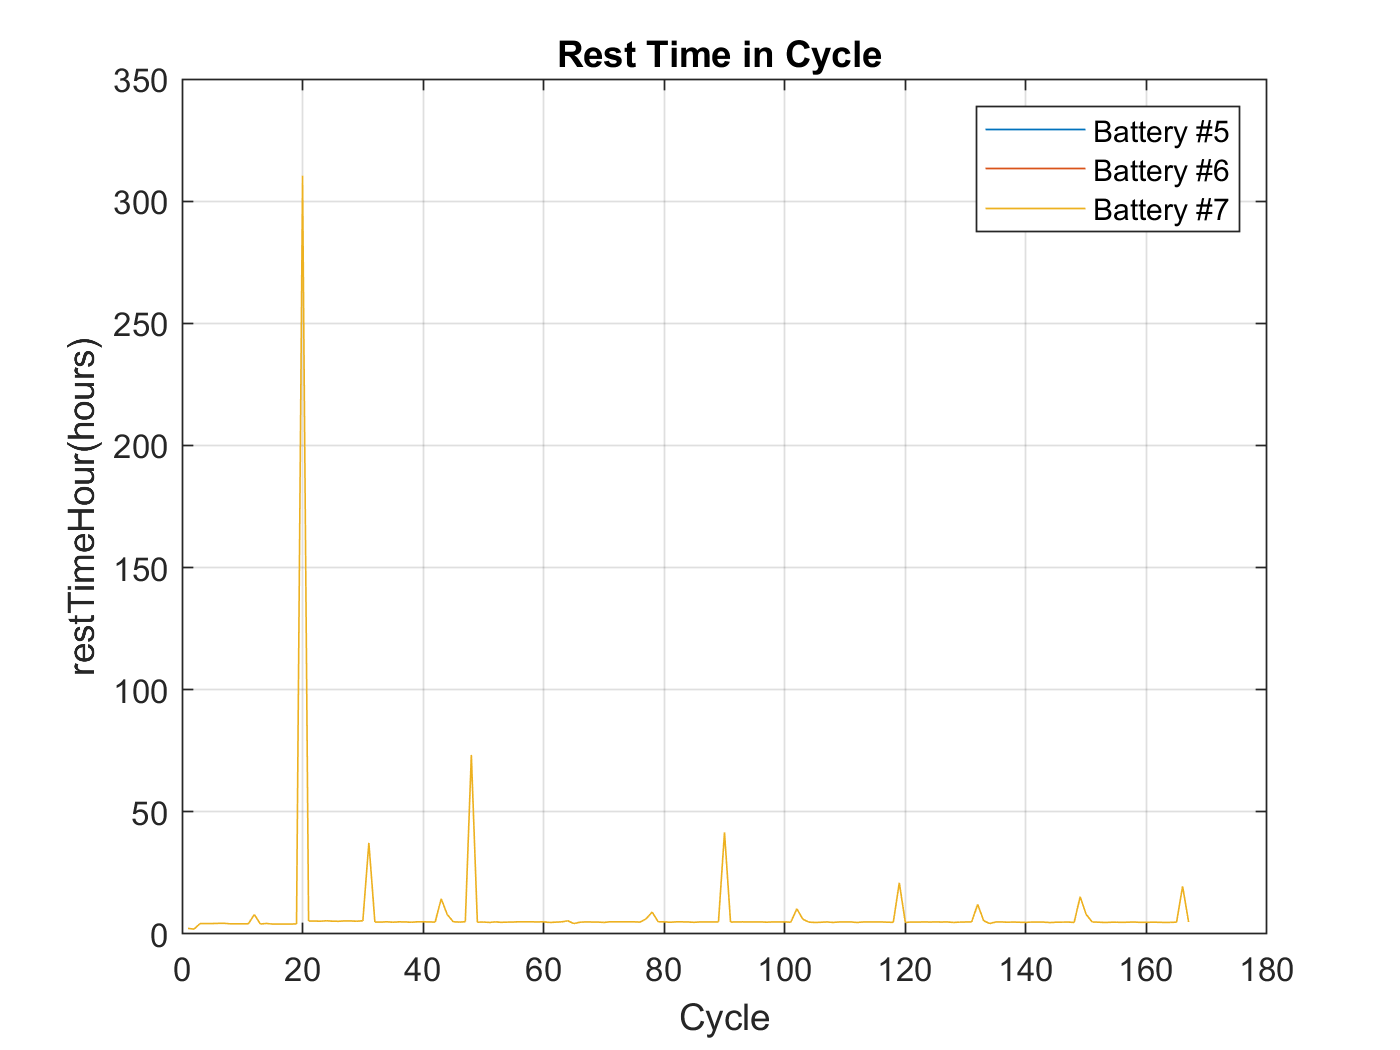



%% remove battery 18 

figure

plot(restTimeHour05), hold on, plot(restTimeHour06), plot(restTimeHour07)
hold off, grid on
xlabel Cycle, ylabel restTimeHour(hours)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Rest Time in Cycle ')

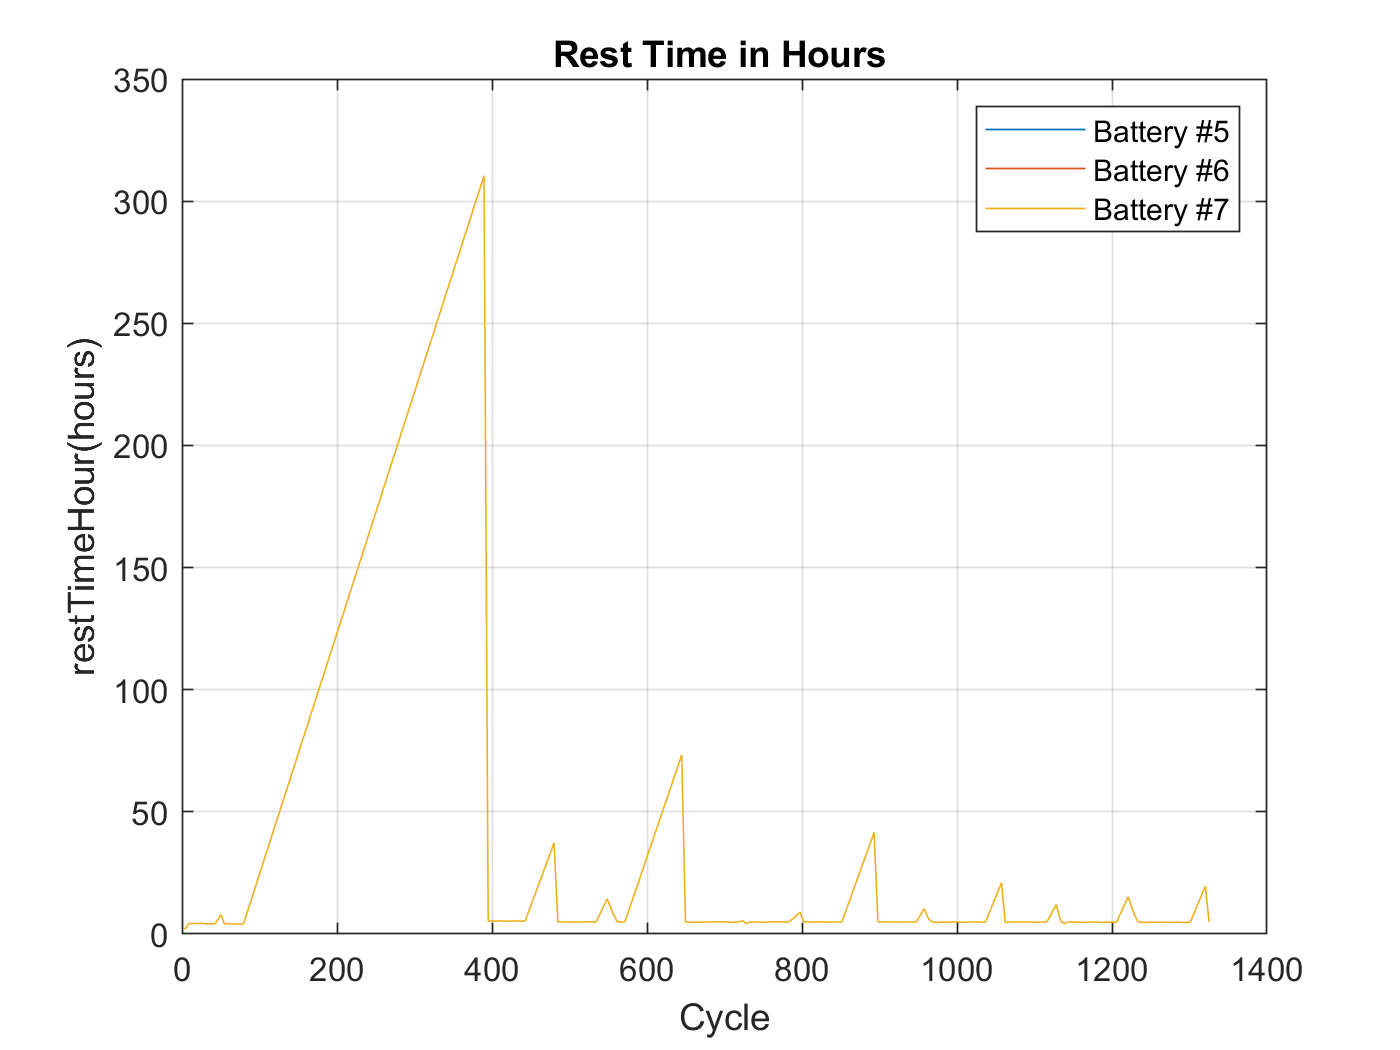


figure
plot(cycleTimeHour05,restTimeHour05), hold on, plot(cycleTimeHour06,restTimeHour06), plot(cycleTimeHour07,restTimeHour07)
hold off, grid on
xlabel Cycle, ylabel restTimeHour(hours)
legend('Battery #5', 'Battery #6', 'Battery #7')
title('Rest Time in Hours ')

%{
%% index
i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;
%}

%% create vector / table
    
regression_vector05 = [ ...
    result05(:, restTimeHourIdx ) ... 
    result05(:, cCcEndTimeSecIdx ) ...
    result05(:, ohmIdx ) ...
    result05(:, pattern_dVoltIdx ) ...
    result05(:, capacityIdx ) ] ;

regression_vector06 = [ ...
    result06(:, restTimeHourIdx ) ... 
    result06(:, cCcEndTimeSecIdx ) ...
    result06(:, ohmIdx ) ...
    result06(:, pattern_dVoltIdx ) ...
    result06(:, capacityIdx ) ] ;

regression_vector07 = [ ...
    result07(:, restTimeHourIdx ) ... 
    result07(:, cCcEndTimeSecIdx ) ...
    result07(:, ohmIdx ) ...
    result07(:, pattern_dVoltIdx ) ...
    result07(:, capacityIdx ) ] ;

regression_vector18 = [ ...
    result18(:, restTimeHourIdx ) ... 
    result18(:, cCcEndTimeSecIdx ) ...
    result18(:, ohmIdx ) ...
    result18(:, pattern_dVoltIdx ) ...
    result18(:, capacityIdx ) ] ;

regression_vector_all = [ ...
    result_all(:, restTimeHourIdx ) ... 
    result_all(:, cCcEndTimeSecIdx ) ...
    result_all(:, ohmIdx ) ...
    result_all(:, pattern_dVoltIdx ) ...
    result_all(:, capacityIdx ) ] ;

regression_vector_05_06_all = [ ...
    result_05_06_all(:, restTimeHourIdx ) ... 
    result_05_06_all(:, cCcEndTimeSecIdx ) ...
    result_05_06_all(:, ohmIdx ) ...
    result_05_06_all(:, pattern_dVoltIdx ) ...
    result_05_06_all(:, capacityIdx ) ] ;

regression_vector05_06 = [ ...
    result05_06(:, restTimeHourIdx ) ... 
    result05_06(:, cCcEndTimeSecIdx ) ...
    result05_06(:, ohmIdx ) ...
    result05_06(:, pattern_dVoltIdx ) ...
    result05_06(:, capacityIdx ) ] ;

regression_vector06_05 = [ ...
    result06_05(:, restTimeHourIdx ) ... 
    result06_05(:, cCcEndTimeSecIdx ) ...
    result06_05(:, ohmIdx ) ...
    result06_05(:, pattern_dVoltIdx ) ...
    result06_05(:, capacityIdx ) ] ;

% works
regression_table05 = array2table(regression_vector05,...
    'VariableNames',{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table06 = array2table(regression_vector06,...
    'VariableNames',{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table05_06 = array2table(regression_vector05_06,...
    'VariableNames',{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table06_05 = array2table(regression_vector06_05,...
    'VariableNames',{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_05_06_all = array2table(regression_vector_05_06_all,...
    'VariableNames',{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table07 = array2table(regression_vector07,...
    'VariableNames',{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table18 = array2table(regression_vector18,...
    'VariableNames',{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt','capacity'});

regression_table_all = array2table(regression_vector_all,...
    'VariableNames',{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt','capacity'});
    
% https://kr.mathworks.com/help/matlab/ref/cell2table.html    
% works
%{
regression_table_5 = array2table(regression_vector05,...
    'VariableNames',{'restTimeHour','cCcEndTimeSec','ohm','capacity'});

regression_table_6 = array2table(regression_vector06,...
    'VariableNames',{'restTimeHour','cCcEndTimeSec','ohm','capacity'});
%}


## corellaton

%{ 
% error after adding pattern_dVolt
figure
[R5,PValue5] = corrplot(regression_vector05,'type','Pearson','testR','on','varNames',{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt','capacity'})
figure
[R6,PValue6] = corrplot(regression_vector06,'type','Pearson','testR','on','varNames',{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt','capacity'})
%}

%% linear regression

% https://kr.mathworks.com/help/stats/fitlm.html
modelspec = ' capacity ~ restTimeHour + cCcEndTimeSec + ohm + pattern_dVolt '

modelspec = ' capacity ~ restTimeHour + cCcEndTimeSec + ohm + pattern_dVolt '

modelspecSingleX = ' capacity ~  cCcEndTimeSec + pattern_dVolt '

modelspecSingleX = ' capacity ~  cCcEndTimeSec + pattern_dVolt '

mdl = fitlm(regression_table_all,modelspec )

mdl = Linear regression model:
    capacity ~ 1 + restTimeHour + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue   
                     __________    __________    _______    ___________

    (Intercept)          1.1721      0.046732     25.082     1.1293e-96
    restTimeHour      0.0003845    0.00013174     2.9186      0.0036426
    cCcEndTimeSec    0.00022996    7.6941e-06     29.888    1.0684e-122
    ohm                 -59.571        7.8231    -7.6147     9.7673e-14
    pattern_dVolt     0.0038261      0.017477    0.21892        0.82678


Number of observations: 632, Error degrees of freedom: 627
Root Mean Squared Error: 0.0792
R-squared: 0.843,  Adjusted R-Squared: 0.842
F-statisti

mdlSingleX = fitlm(regression_table_all,modelspecSingleX )

mdlSingleX = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat        pValue   
                     __________    __________    ________    ___________

    (Intercept)         0.90528      0.032272      28.052    6.3805e-113
    cCcEndTimeSec    0.00027648    5.1483e-06      53.703    4.0043e-237
    pattern_dVolt    -0.0071911      0.018365    -0.39157        0.69551


Number of observations: 632, Error degrees of freedom: 629
Root Mean Squared Error: 0.0834
R-squared: 0.825,  Adjusted R-Squared: 0.824
F-statistic vs. constant model: 1.48e+03, p-value = 9.62e-239


mdl5 = fitlm(regression_table05,modelspec )

mdl5 = Linear regression model:
    capacity ~ 1 + restTimeHour + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    restTimeHour     9.9644e-05    0.00018723    0.53221       0.59531
    cCcEndTimeSec    0.00023258     1.218e-05     19.095    2.5331e-43
    ohm                 -77.422        12.271    -6.3094    2.5669e-09
    pattern_dVolt       0.80642      0.041731     19.324    6.6029e-44


Number of observations: 167, Error degrees of freedom: 163
Root Mean Squared Error: 0.0585
R-squared: 0.908,  Adjusted R-Squared: 0.906
F-statistic vs. 

mdlSingleX5 = fitlm(regression_table05,modelspecSingleX )

mdlSingleX5 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)               0             0       NaN           NaN
    cCcEndTimeSec    0.00029414    8.2725e-06    35.556    5.5345e-79
    pattern_dVolt       0.55549      0.014258     38.96     8.283e-85


Number of observations: 167, Error degrees of freedom: 165
Root Mean Squared Error: 0.0651
R-squared: 0.885,  Adjusted R-Squared: 0.884
F-statistic vs. constant model: 1.26e+03, p-value = 2.92e-79

mdl6 = fitlm(regression_table06,modelspec )

mdl6 = Linear regression model:
    capacity ~ 1 + restTimeHour + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    restTimeHour     0.00025433    0.00019281     1.3191       0.18901
    cCcEndTimeSec    0.00018715    1.3409e-05     13.957    1.4109e-29
    ohm                 -118.73        13.172    -9.0134    5.3855e-16
    pattern_dVolt       0.89339      0.041803     21.371    5.2556e-49


Number of observations: 167, Error degrees of freedom: 163
Root Mean Squared Error: 0.0601
R-squared: 0.944,  Adjusted R-Squared: 0.943
F-statistic vs. 

mdlSingleX6 = fitlm(regression_table06,modelspecSingleX )

mdlSingleX6 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue   
                     __________    __________    ______    ___________

    (Intercept)               0             0       NaN            NaN
    cCcEndTimeSec    0.00029767    7.0719e-06    42.092     8.1039e-90
    pattern_dVolt       0.52372     0.0097702    53.603    7.2219e-106


Number of observations: 167, Error degrees of freedom: 165
Root Mean Squared Error: 0.074
R-squared: 0.915,  Adjusted R-Squared: 0.914
F-statistic vs. constant model: 1.77e+03, p-value = 3.72e-90

mdl5_6 = fitlm(regression_table05_06,modelspec )

mdl5_6 = Linear regression model:
    capacity ~ 1 + restTimeHour + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    restTimeHour     0.00011532    9.1015e-05      1.267       0.21069
    cCcEndTimeSec    1.4842e-06    1.0874e-05    0.13648       0.89196
    ohm                 -44.541        6.4371    -6.9195    6.0787e-09
    pattern_dVolt        1.2596      0.027075     46.522    1.1792e-44


Number of observations: 58, Error degrees of freedom: 54
Root Mean Squared Error: 0.0281
R-squared: 0.502,  Adjusted R-Squared: 0.474
F-statistic vs. 

mdl6_5 = fitlm(regression_table06_05,modelspec )

mdl6_5 = Linear regression model:
    capacity ~ 1 + restTimeHour + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    restTimeHour     0.00018901    0.00019281     0.9803       0.33185
    cCcEndTimeSec    1.6487e-05    2.1383e-05    0.77105       0.44445
    ohm                 -109.36         14.25     -7.674    6.8709e-10
    pattern_dVolt        1.2099      0.052128      23.21    9.6519e-28


Number of observations: 53, Error degrees of freedom: 49
Root Mean Squared Error: 0.0595
R-squared: 0.637,  Adjusted R-Squared: 0.615
F-statistic vs. 

mdl_05_06 = fitlm(regression_table_05_06_all,modelspec )

mdl_05_06 = Linear regression model:
    capacity ~ 1 + restTimeHour + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)         0.74276      0.068148     10.899    8.0165e-24
    restTimeHour     0.00018433    0.00013511     1.3643       0.17339
    cCcEndTimeSec    0.00021161    9.0466e-06     23.391    5.8902e-72
    ohm                 -96.094        8.9655    -10.718    3.4391e-23
    pattern_dVolt       0.38171      0.033809      11.29    3.3318e-25


Number of observations: 334, Error degrees of freedom: 329
Root Mean Squared Error: 0.0597
R-squared: 0.93,  Adjusted R-Squared: 0.929
F-statistic 


mdl7 = fitlm(regression_table07,modelspec )

mdl7 = Linear regression model:
    capacity ~ 1 + restTimeHour + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    restTimeHour      7.347e-05    0.00017876      0.411       0.68162
    cCcEndTimeSec    0.00021168    1.2727e-05     16.633    7.1589e-37
    ohm                 -104.22        11.577    -9.0023    5.7612e-16
    pattern_dVolt       0.67293      0.031288     21.507     2.451e-49


Number of observations: 167, Error degrees of freedom: 163
Root Mean Squared Error: 0.0559
R-squared: 0.882,  Adjusted R-Squared: 0.88
F-statistic vs. c

mdlSingleX7 = fitlm(regression_table07,modelspecSingleX )

mdlSingleX7 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate        SE        tStat       pValue  
                     __________    _________    ______    __________

    (Intercept)               0            0       NaN           NaN
    cCcEndTimeSec    0.00029566    1.069e-05    27.658    1.1928e-63
    pattern_dVolt       0.41331     0.015013     27.53    2.2365e-63


Number of observations: 167, Error degrees of freedom: 165
Root Mean Squared Error: 0.0682
R-squared: 0.823,  Adjusted R-Squared: 0.821
F-statistic vs. constant model: 765, p-value = 7.55e-64


mdl18 = fitlm(regression_table18,modelspec )

mdl18 = Linear regression model:
    capacity ~ 1 + restTimeHour + cCcEndTimeSec + ohm + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE         tStat       pValue  
                     __________    __________    _______    __________

    (Intercept)               0             0        NaN           NaN
    restTimeHour      0.0010816    0.00033911     3.1894     0.0017991
    cCcEndTimeSec    0.00019672    1.6367e-05     12.019     1.218e-22
    ohm                  617.89         91.45     6.7565    4.6798e-10
    pattern_dVolt       -0.3477       0.13849    -2.5106       0.01332


Number of observations: 131, Error degrees of freedom: 127
Root Mean Squared Error: 0.0881
R-squared: 0.681,  Adjusted R-Squared: 0.674
F-statistic vs.

mdlSingleX18 = fitlm(regression_table18,modelspecSingleX )

mdlSingleX18 = Linear regression model:
    capacity ~ 1 + cCcEndTimeSec + pattern_dVolt

Estimated Coefficients:
                      Estimate         SE        tStat       pValue  
                     __________    __________    ______    __________

    (Intercept)               0             0       NaN           NaN
    cCcEndTimeSec    0.00022883    1.8405e-05    12.433     9.201e-24
    pattern_dVolt       0.58303      0.027413    21.268    7.7041e-44


Number of observations: 131, Error degrees of freedom: 129
Root Mean Squared Error: 0.104
R-squared: 0.545,  Adjusted R-Squared: 0.542
F-statistic vs. constant model: 155, p-value = 8.13e-24




%% get  hat 
% https://kr.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html

capacityHat = predict(mdl,regression_table05(:,{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacitySingleXHat = predict(mdlSingleX,regression_table05(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat5 = predict(mdl5,regression_table05(:,{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacitySingleXHat5 = predict(mdlSingleX5,regression_table05(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat6 = predict(mdl6,regression_table06(:,{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacitySingleXHat6 = predict(mdlSingleX6,regression_table06(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat7 = predict(mdl7,regression_table07(:,{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacitySingleXHat7 = predict(mdlSingleX7,regression_table07(:,{'cCcEndTimeSec','pattern_dVolt'}))';

capacityHat18 = predict(mdl18,regression_table18(:,{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt'}))';
capacitySingleXHat18 = predict(mdlSingleX18,regression_table18(:,{'cCcEndTimeSec','pattern_dVolt'}))';

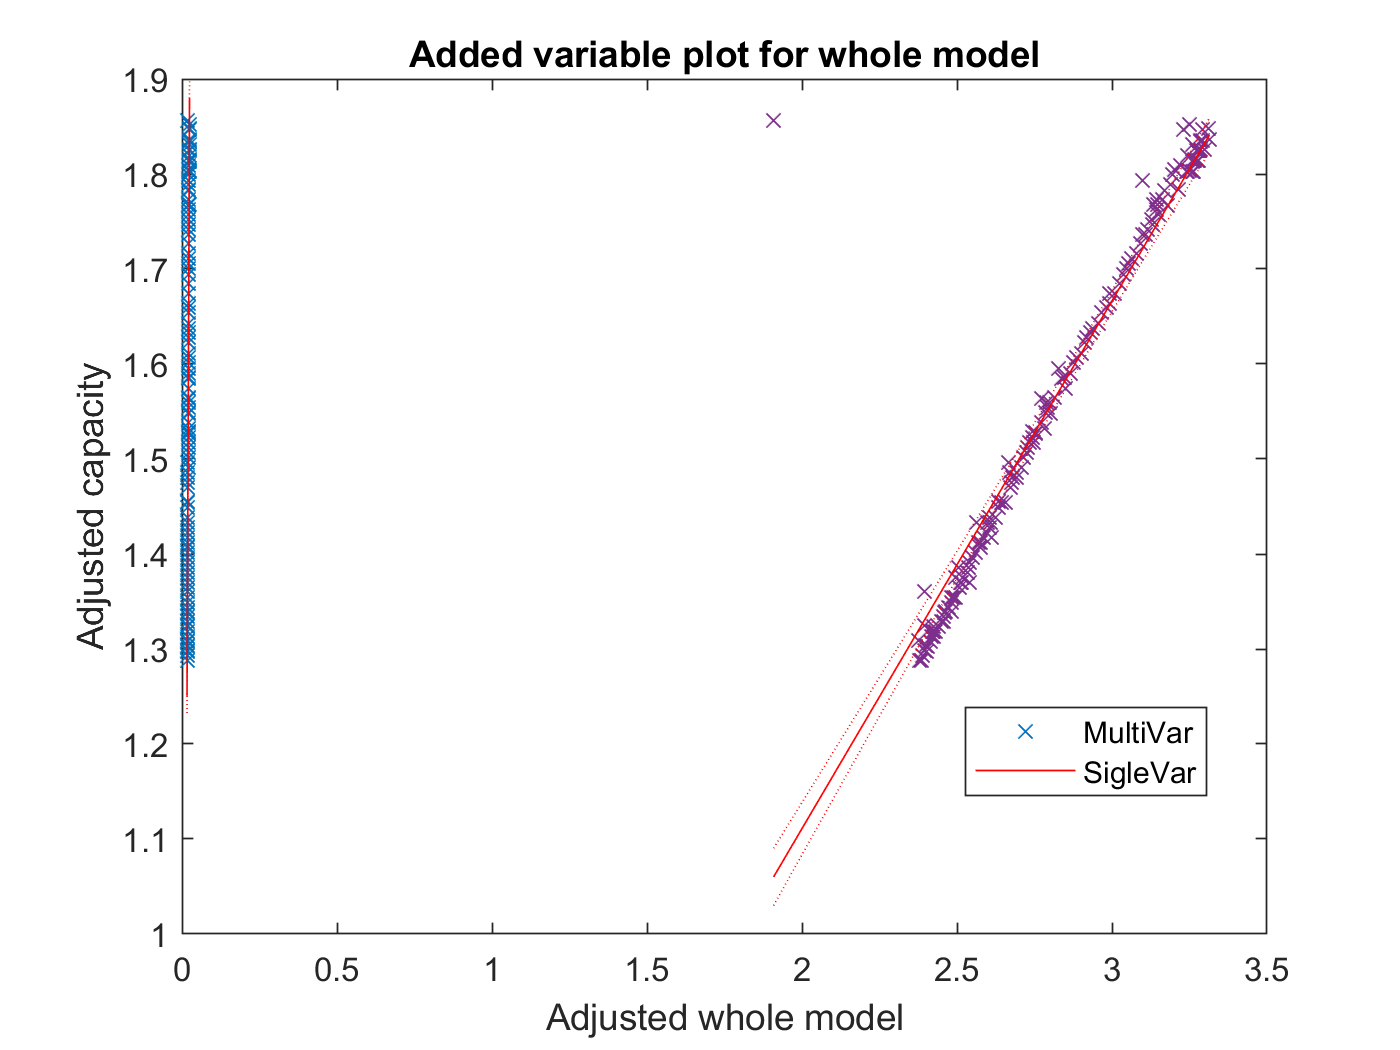


%% plot - model
figure
plot(mdl5)
hold on 
plot(mdlSingleX5)
hold off
legend('MultiVar','SigleVar')

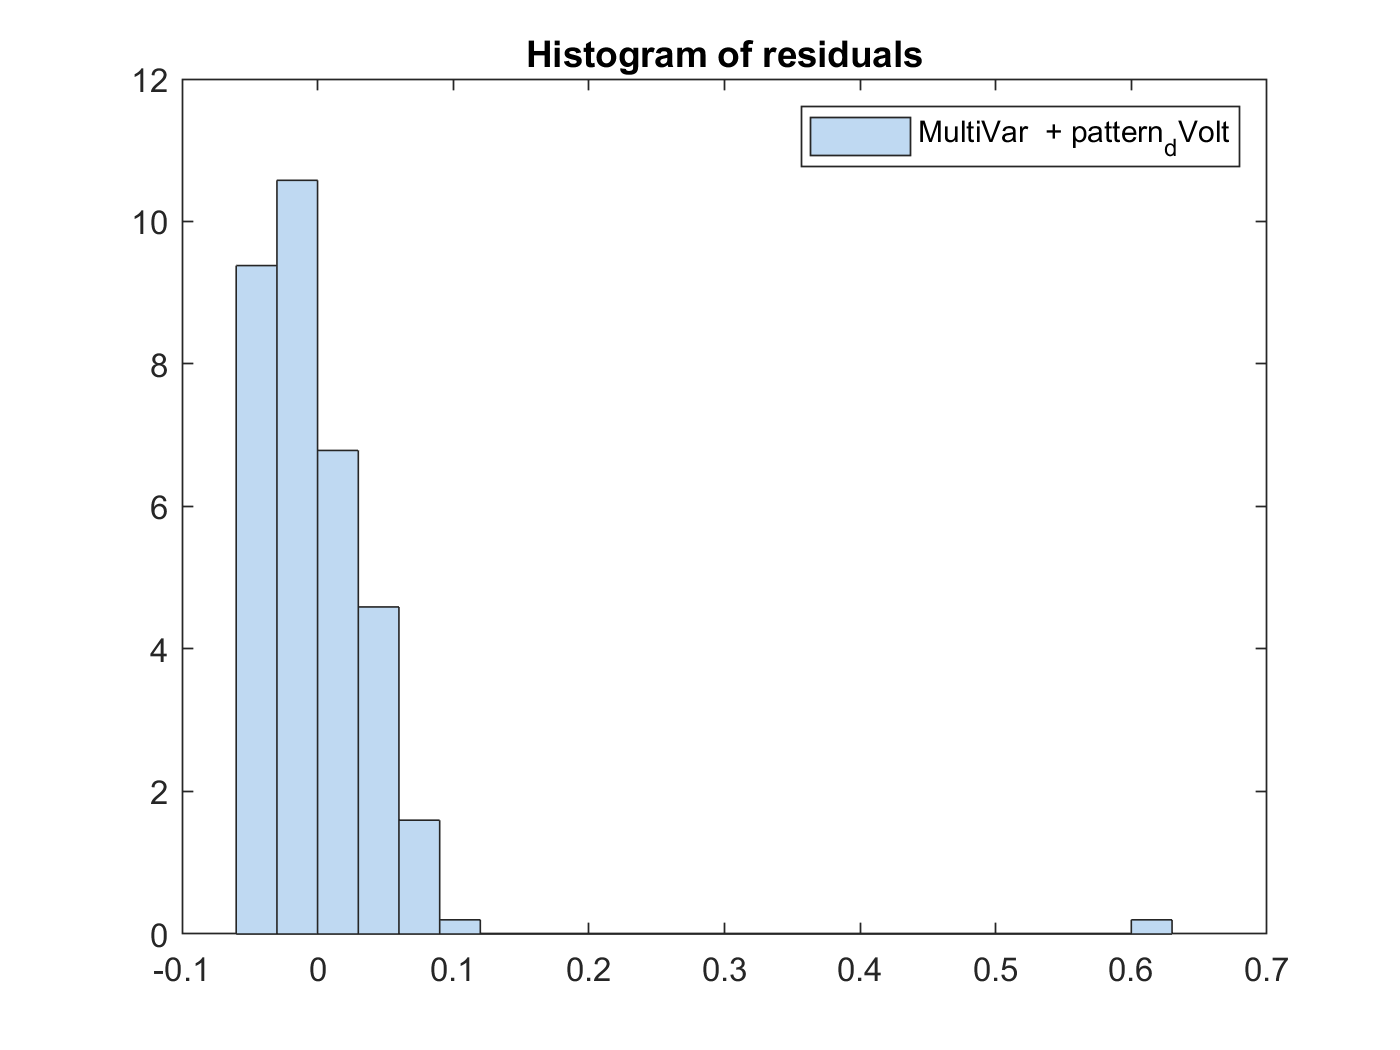



%% plot - residuals 
plotResiduals(mdl5)
legend('MultiVar  + pattern_dVolt')

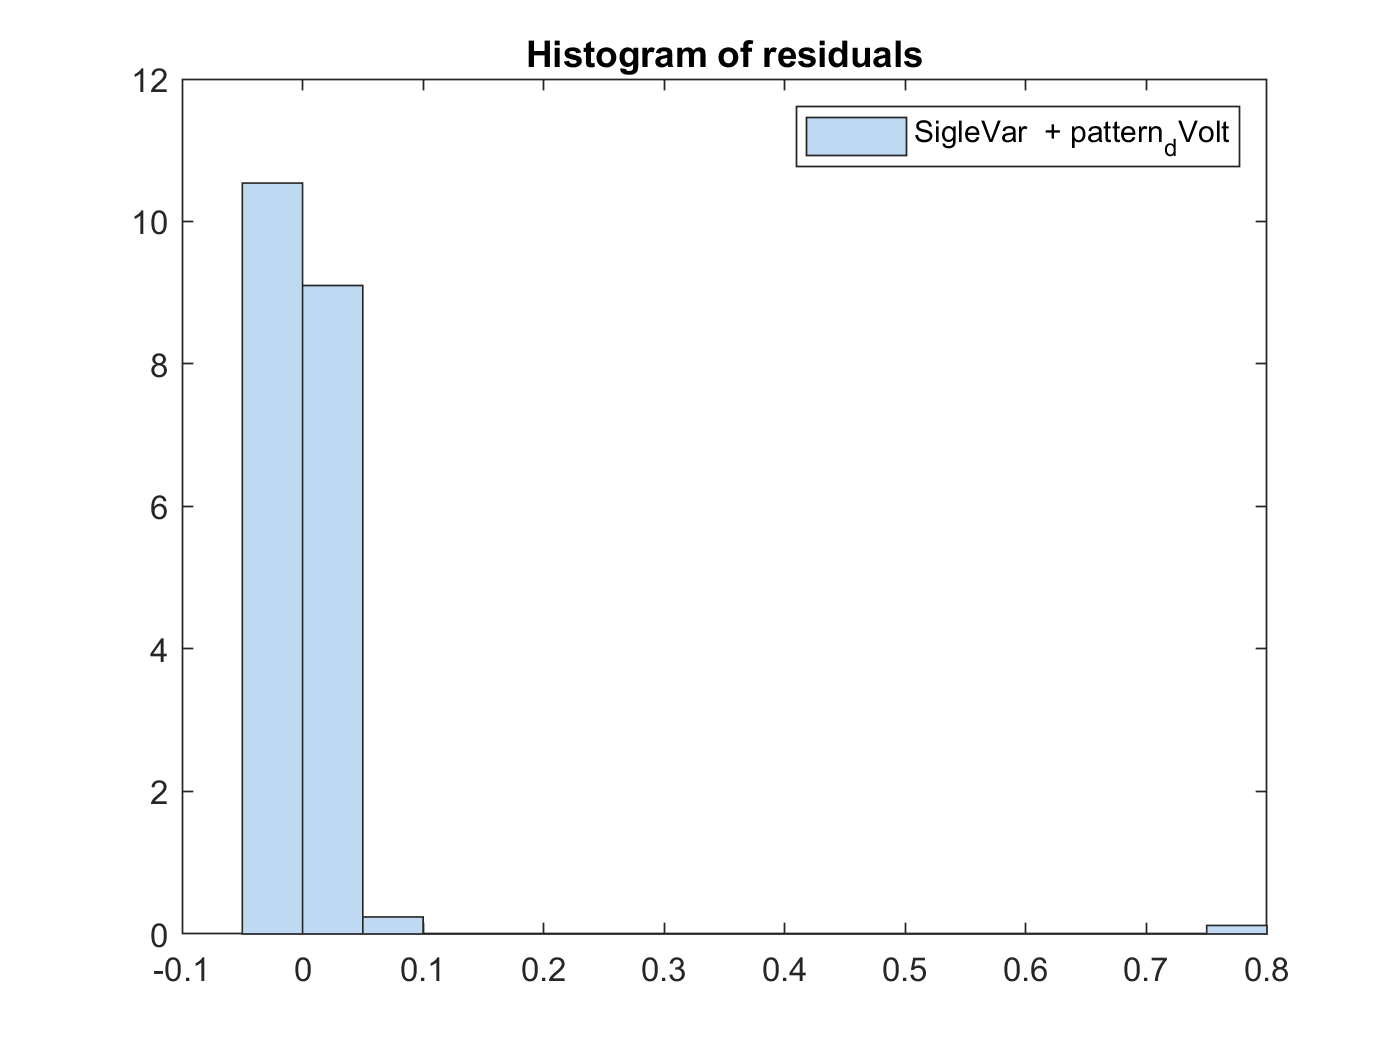

figure
plotResiduals(mdlSingleX5)
legend('SigleVar  + pattern_dVolt')

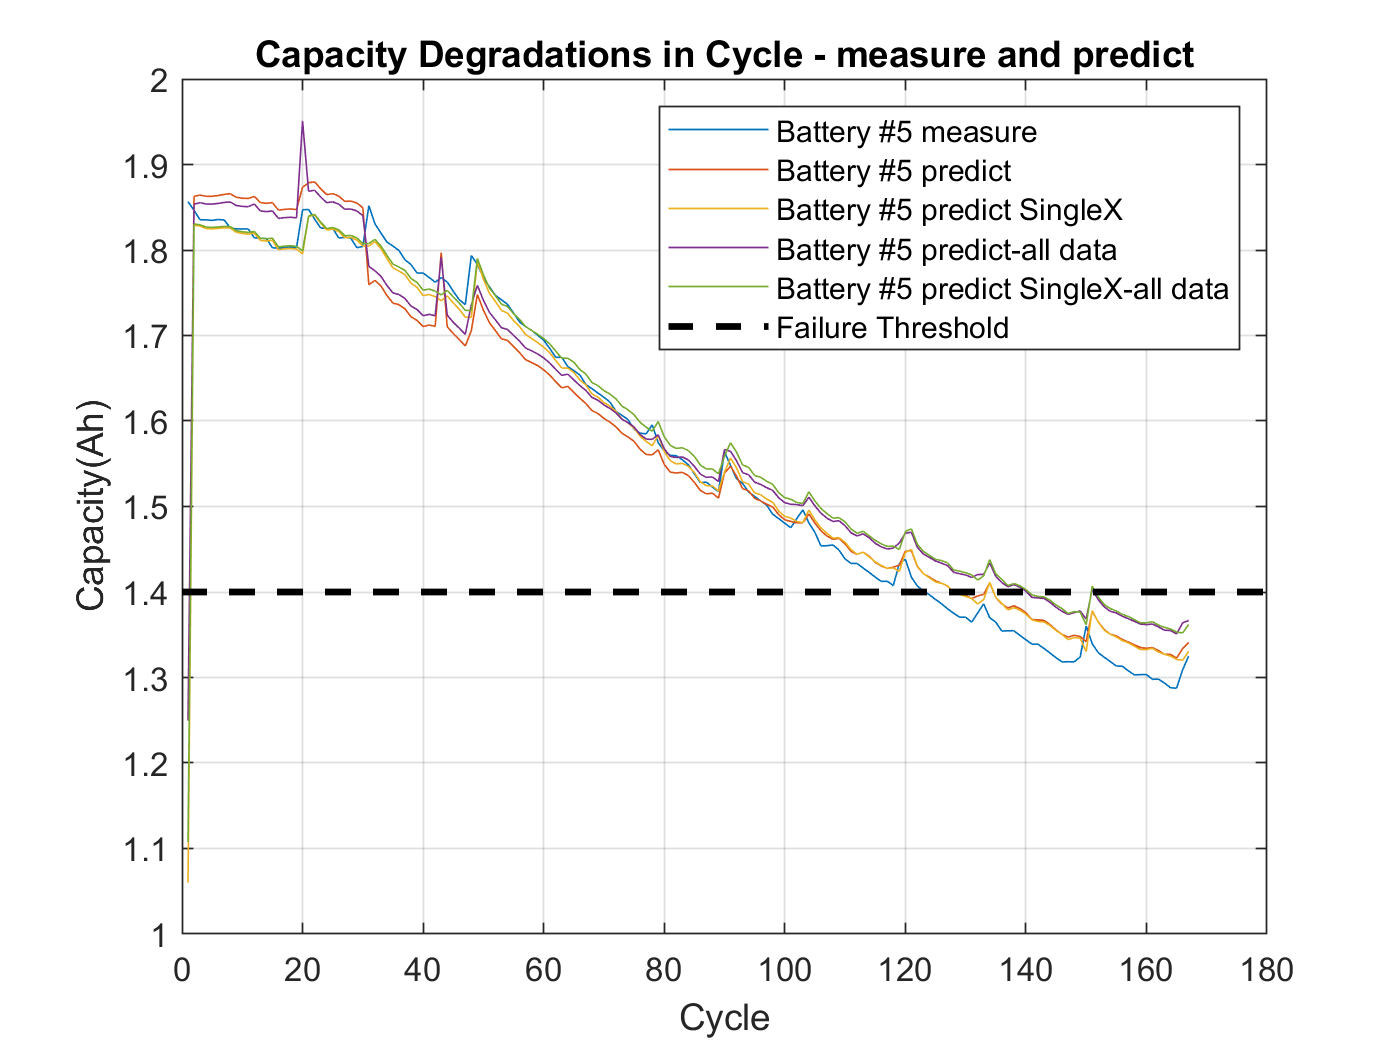

figure


%% plot - hat 
figure
plot(capacity05), hold on, plot(capacityHat5),plot(capacitySingleXHat5),plot(capacityHat),plot(capacitySingleXHat)
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 measure', 'Battery #5 predict', 'Battery #5 predict SingleX','Battery #5 predict-all data', 'Battery #5 predict SingleX-all data','Failure Threshold')
title('Capacity Degradations in Cycle - measure and predict')

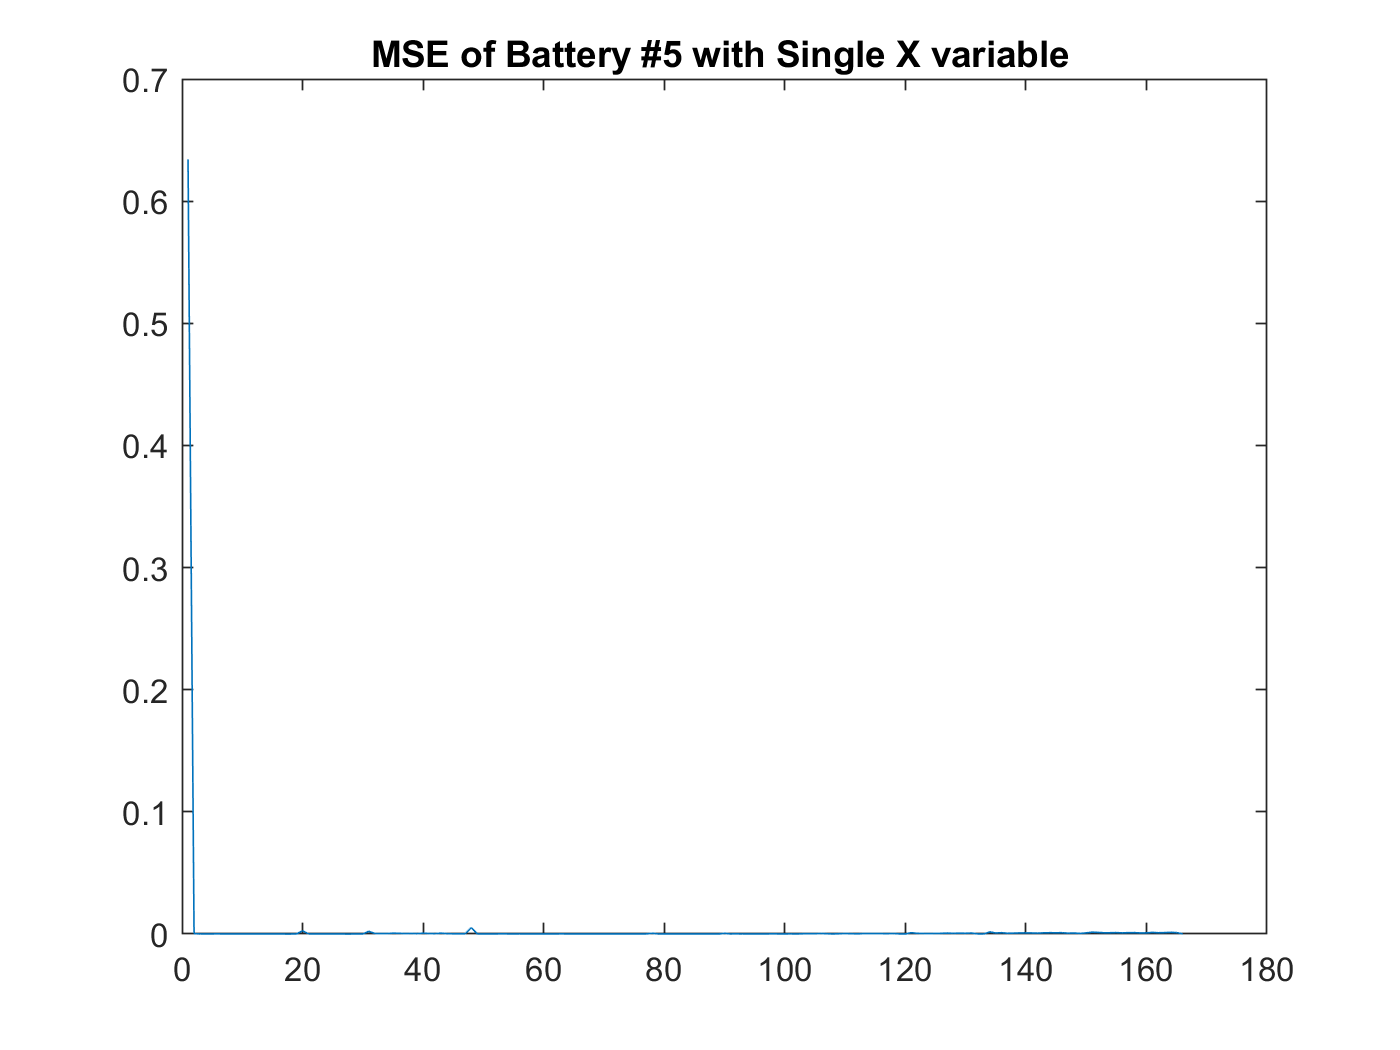


%%

% https://kr.mathworks.com/matlabcentral/answers/4064-rmse-root-mean-square-error
% https://kr.mathworks.com/matlabcentral/answers/234047-plot-mean-square-error

%%
% https://kr.mathworks.com/matlabcentral/answers/26944-plotting-rmse
% not works
%{
dt = 0.1;
k = length(capacity05);
capacityT5 = capacity05';
capacitySingleXHatT5 = capacitySingleXHat5';
err(k)=sqrt(sum(capacityT5(1:k,1)-capacitySingleXHatT5(1:k,1))^2/k);
t(k) = dt*k;  %simulation time, where dt is time for one increment of loop
%outside of loop:
figure
plot(err,t)
title('RMSE of Battery #5 with Single X variable ')
%}


%%
N = length(capacity05);
for i = 1:N-1
    mse_var(i) = mean((capacity05(i)-capacitySingleXHat5(i)).^2);
end
figure
plot(abs(mse_var));
title('MSE of Battery #5 with Single X variable ')


%% summary
% https://kr.mathworks.com/help/stats/linearmodel.html
anova(mdl5,'summary')

ans = 3×5 table
                 SumSq     DF      MeanSq        F         pValue  
                _______    ___    _________    ______    __________

    Total        6.0538    166     0.036469                        
    Model        5.4958      3       1.8319    535.12    4.0344e-84
    Residual    0.55802    163    0.0034234                        


anova(mdlSingleX5,'summary')

ans = 3×5 table
                 SumSq     DF      MeanSq        F         pValue  
                _______    ___    _________    ______    __________

    Total        6.0538    166     0.036469                        
    Model        5.3549      1       5.3549    1264.3    2.9152e-79
    Residual    0.69888    165    0.0042356                        



mdl5.MSE

ans = 0.0034

mdl5.RMSE % 0.0131

ans = 0.0585

mdl5.SSE

ans = 0.5580

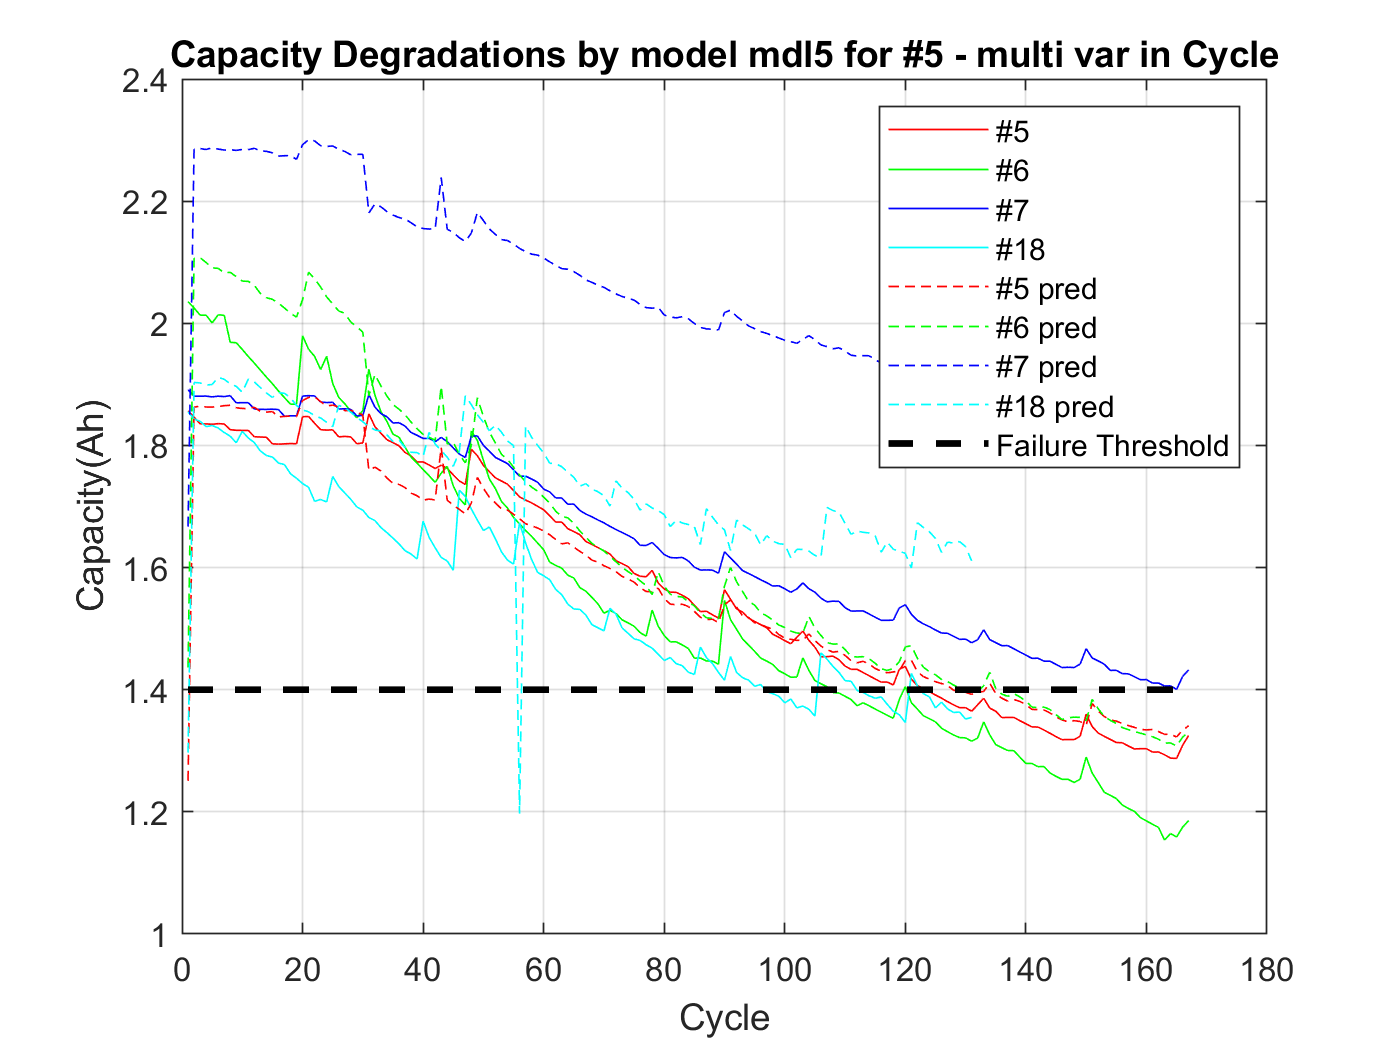

%% model mdl5 from battery 5 - predict other battery
pred6_by_mdl5 = predict(mdl5,regression_table06(:,{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt'}));
pred7_by_mdl5 = predict(mdl5,regression_table07(:,{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt'}));
pred18_by_mdl5 = predict(mdl5,regression_table18(:,{'restTimeHour','cCcEndTimeSec','ohm','pattern_dVolt'}));

%% plot
cycle_number = length(capacity05);

figure
plot(capacity05,'r'), hold on, plot(capacity06,'g'), plot(capacity07,'b'), plot(capacity18,'c')
plot(capacityHat5,'r--'), hold on, plot(pred6_by_mdl5,'g--'), plot(pred7_by_mdl5,'b--'), plot(pred18_by_mdl5,'c--')
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('#5', '#6', '#7', '#18','#5 pred', '#6 pred', '#7 pred', '#18 pred','Failure Threshold')
title('Capacity Degradations by model mdl5 for #5 - multi var in Cycle')

5+6, 5-6,6-5 

평가 5-6 <= mdl5, mdl6 ,mdl5-6, mdl6-5,mdl 5,6 

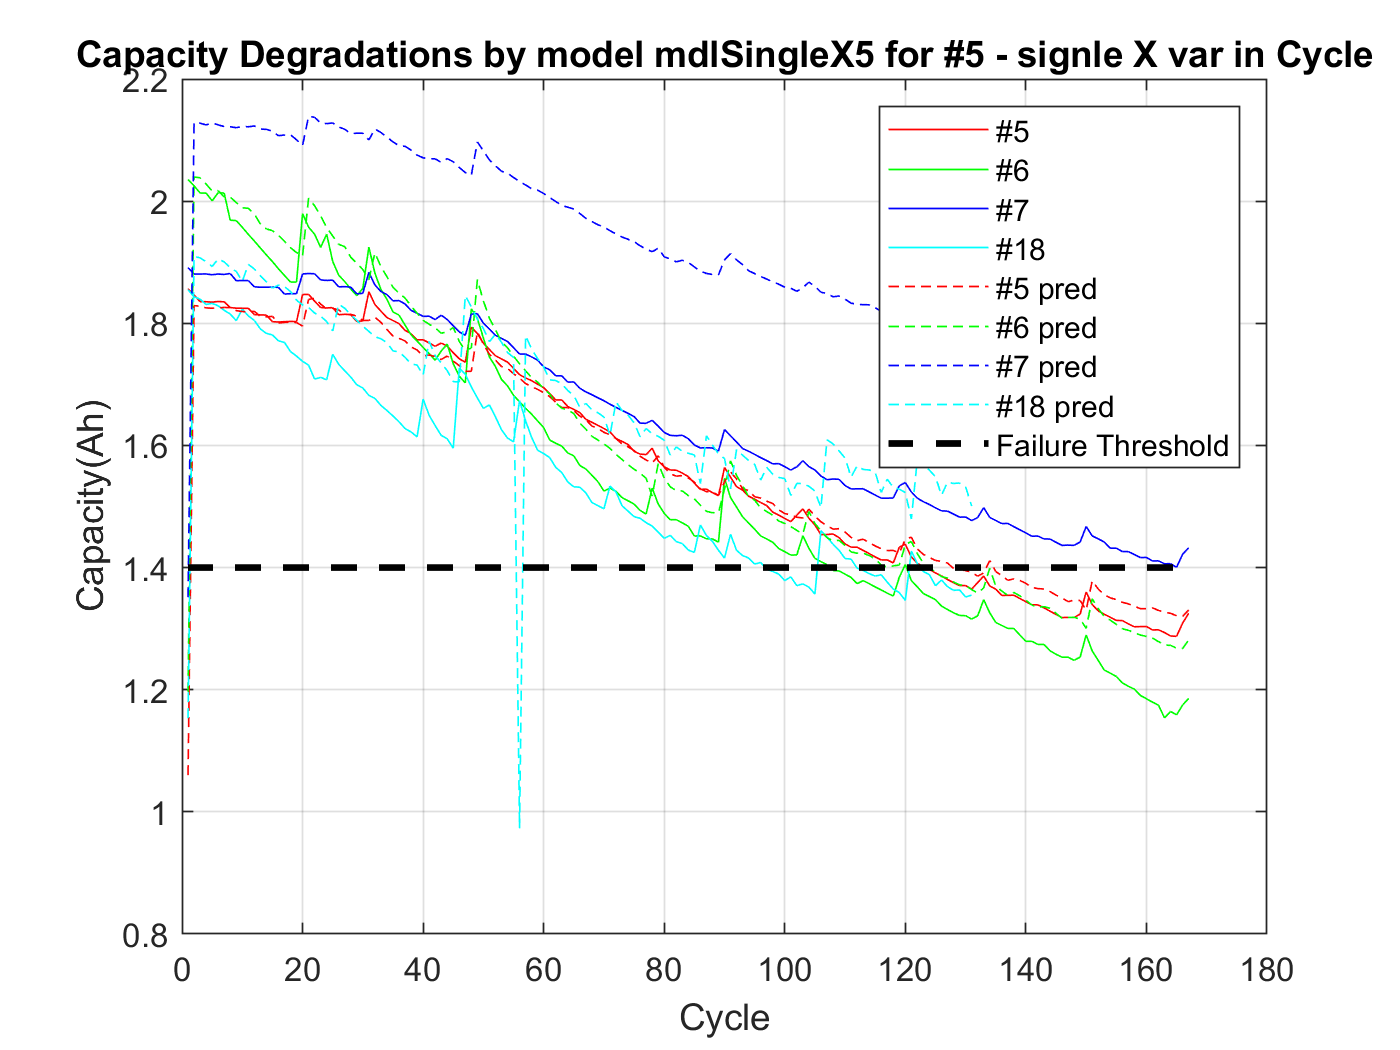

%% model from battery 5 - predict other battery
pred6_by_mdlSingleX5 = predict(mdlSingleX5,regression_table06(:,{'cCcEndTimeSec','pattern_dVolt'}));
pred7_by_mdlSingleX5 = predict(mdlSingleX5,regression_table07(:,{'cCcEndTimeSec','pattern_dVolt'}));
pred18_by_mdlSingleX5 = predict(mdlSingleX5,regression_table18(:,{'cCcEndTimeSec','pattern_dVolt'}));

%% plot
cycle_number = length(capacity05);

figure
plot(capacity05,'r'), hold on, plot(capacity06,'g'), plot(capacity07,'b'), plot(capacity18,'c')
plot(capacitySingleXHat5,'r--'), hold on, plot(pred6_by_mdlSingleX5,'g--'), plot(pred7_by_mdlSingleX5,'b--'), plot(pred18_by_mdlSingleX5,'c--')
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('#5', '#6', '#7', '#18','#5 pred', '#6 pred', '#7 pred', '#18 pred','Failure Threshold')
title('Capacity Degradations by model mdlSingleX5 for #5 - signle X var in Cycle')




% 18 번 6번은 잘 적용이 안되고 특히 18번은 오류가 많다.
% 아무래도 cCcEndTimeSec 값이 해당 배터리에서 적용이 잘 안되는 것 같다.



% https://kr.mathworks.com/matlabcentral/answers/386493-rmse-between-two-variables
mdl5.RMSE

ans = 0.0585

mdl6.RMSE

ans = 0.0601

mdl7.RMSE

ans = 0.0559

mdl18.RMSE

ans = 0.0881


RMSE_5 = sqrt(mean(( capacity05 - capacityHat5 ).^2))

RMSE_5 = 0.0578

RMSE_6 = sqrt(mean(( capacity06 - capacityHat6 ).^2))

RMSE_6 = 0.0594

RMSE_7 = sqrt(mean(( capacity07 - capacityHat7 ).^2))

RMSE_7 = 0.0552

RMSE_18 = sqrt(mean(( capacity18 - capacityHat18 ).^2))

RMSE_18 = 0.0868


RMSE_5_by_mdl5 = sqrt(mean(( capacity05 - capacityHat5 ).^2))

RMSE_5_by_mdl5 = 0.0578

RMSE_6_by_mdl5 = sqrt(mean(( capacity06 - pred6_by_mdl5' ).^2))

RMSE_6_by_mdl5 = 0.1055

RMSE_7_by_mdl5 = sqrt(mean(( capacity07 - pred7_by_mdl5' ).^2))

RMSE_7_by_mdl5 = 0.4028

RMSE_18_by_mdl5 = sqrt(mean(( capacity18 - pred18_by_mdl5' ).^2))

RMSE_18_by_mdl5 = 0.2115


mdlSingleX5.RMSE

ans = 0.0651

mdlSingleX6.RMSE

ans = 0.0740

mdlSingleX7.RMSE

ans = 0.0682

mdlSingleX18.RMSE

ans = 0.1045

% https://kr.mathworks.com/matlabcentral/answers/286146-why-rmse-obtained-by-fitlm-in-matlab-does-not-match-with-rmse-calculated-in-excel
% As you can see, dividing by the degrees of freedom is what fitlm must be doing.
% sqrt(sum((y - lm.predict(x)).^2/100)) 
% sqrt(sum((y - lm.predict(x)).^2/100))  -> dividing by the degrees of freedom
RMSE_SingleX_5 = sqrt(mean(( capacity05 - capacitySingleXHat5 ).^2))

RMSE_SingleX_5 = 0.0647

RMSE_SingleX_6 = sqrt(mean(( capacity06 - capacitySingleXHat6 ).^2))

RMSE_SingleX_6 = 0.0736

RMSE_SingleX_7 = sqrt(mean(( capacity07 - capacitySingleXHat7 ).^2))

RMSE_SingleX_7 = 0.0678

RMSE_SingleX_18 = sqrt(mean(( capacity18 - capacitySingleXHat18 ).^2))

RMSE_SingleX_18 = 0.1037


RMSE_5_by_mdlSingleX5 = sqrt(mean(( capacity05 - capacitySingleXHat5 ).^2))

RMSE_5_by_mdlSingleX5 = 0.0647

RMSE_6_by_mdlSingleX5 = sqrt(mean(( capacity06 - pred6_by_mdlSingleX5' ).^2))

RMSE_6_by_mdlSingleX5 = 0.0869

RMSE_7_by_mdlSingleX5 = sqrt(mean(( capacity07 - pred7_by_mdlSingleX5' ).^2))

RMSE_7_by_mdlSingleX5 = 0.2883

RMSE_18_by_mdlSingleX5 = sqrt(mean(( capacity18 - pred18_by_mdlSingleX5' ).^2))

RMSE_18_by_mdlSingleX5 = 0.1584


%% ARIMA 
% https://www.kaggle.com/sumi25/understand-arima-and-tune-p-d-q
% https://machinelearningmastery.com/arima-for-time-series-forecasting-with-python/

